## **The following code section captures live video from a webcam, creates frames from it, resize the frame to 227x227, and feeds it to Bag of Visual Words trained machine learning algorithm, which then makes a 'guess' at what the image that has been placed in front of it is.**

% --------------------------------------
% % Initialize variable needed for program
% --------------------------------------
PreviousGuessCounter = 0;                     % What is the current count for the same guess
PreviousGuess = 0;                            % What was the last guess the algorithm provided
nNumberOfConsecutiveSameGuessesNeeded = 2;    % # of same consecutive guesses needed for a positive ID
newCategoryClassifier = categoryClassifier;

vid = videoinput('winvideo');

An exception occurred.
There is no available device.



% Configure the object for manual trigger mode.
triggerconfig(vid, 'manual');
start(vid);

An exception occurred.
There is no available device.


oneChannel = 227×227 uint8 matrix
    38    36    35    33    32    32    35    38    41    42    41    41    39    37    36    35    36    38    39    39    40    39    39    38    36    35    35    37    39    41    40    39    39    38    37    35    35    37    38    39    40    39    39    38    37    36    35    36    37    38
    35    34    34    33    34    34    35    37    38    38    38    38    37    37    37    37    37    37    36    37    36    36    36    36    37    36    36    36    36    36    37    37    37    36    35    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    34    34    34    33    33    34    35    36    38    37    37    37    37    37    37    36    36    36    37    37    36    36    37    37    36    37    36    36    37    37    36    36    36    36    36    37    37    37    37    37    37    37    38    37    37    37    38    38    38    38
    39    38    38    39    39    39    40    42    44    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     5     0     0     0     0     0     2    10    10    10     9     7     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     7    10    12    10    11     8     5     2     1     4     7     9     8     7     6     4     2     0     0     0     7     8     9     9     8     6     3     1     2     2     2     2     2     2     2     1     0     0     0     0     0     0     1     1     3     3     2     2     1     1     0     0     5     2     1     0     0     0     0     0     0     0     0     0     0     1     1     4     8    10    10    10    10    10    10    10     8     8     8     8     8     8     8     7    11     8     7     6     4     3     0     0     3     3     3     3     3     3     3     0     0     0     0     0    14    35    42    40    47    53    57    58    57    53    48    48    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    39    41    41    41    41    38    36    35    35    36    38    39    39    40    39    38    38    36    35    35    37    38    41    41    39    39    38    36    35    35    36    37    38    39    39    39    38    36    35    34    35    36    38
    35    34    34    33    34    34    35    37    38    38    37    38    37    37    37    36    36    37    36    36    36    36    37    36    37    36    36    36    36    36    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    35    34    34    33    33    34    34    36    38    38    37    37    36    37    37    36    36    36    37    36    36    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    38    37    37    38    38    38    38
    39    38    39    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     6     3     0     0     0     1     8    10    10    10     9     8     5     3     0     0     0     0     0     1     0     1     0     0     0     0     2     8    11    13    11     9     6     2     0     0     0     1     4     7     6     4     2     0     0     0     0     3     4     5     5     6     4     1     0     0     0     1     2     2     2     3     1     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7     7     8     8     8     9     9    11    10     8     7     7     8    10    10     9     7     7     6     5     4     3     2     5     5     5     4     3     2     2     0     0     0     0     0    13    30    37    36    45    50    54    56    54    50    46    46    53    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    35    33    32    32    35    39    41    42    41    41    38    37    36    35    36    38    39    39    39    40    39    37    36    35    35    37    38    41    40    39    39    39    36    35    35    36    38    39    39    39    39    38    37    36    35    35    36    38
    35    34    33    34    34    34    35    37    39    38    38    38    37    37    37    37    37    36    36    37    36    36    36    37    37    36    36    36    36    37    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    35    34    34    34    33    34    35    36    38    38    37    37    36    37    37    37    36    36    36    36    37    36    36    36    37    37    36    36    36    37    36    36    36    36    37    36    37    37    37    37    37    37    37    37    37    38    38    38    37    38
    39    38    38    39    39    39    40    42    44    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    16     9     6     1     0     0     0     5    13    11     6     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     7    10    12    10    11     7     2     0     0     1     6     9     8     7     6     4     1     0     0     0     4     6     9    11    10     7     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     4     3     2     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     7     9     9    10    10    11    11    11    12    11     9     8     8     9    11    11     9     7     6     5     1     0     0     0     1     1     1     1     1     1     1     0     0     0     0     0    11    32    38    35    45    50    54    56    54    50    46    46    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    31    32    35    38    41    41    41    41    38    36    35    34    36    37    38    39    39    39    39    37    35    34    34    36    38    40    40    39    39    37    36    34    35    36    37    38    39    39    39    38    36    35    34    35    36    37
    34    33    33    33    34    33    35    37    38    38    37    37    37    37    37    37    36    36    36    36    36    35    36    37    36    36    36    36    35    36    37    37    37    36    35    35    35    36    35    35    35    35    35    35    35    35    35    36    35    36
    34    34    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    37    37    37    36    37    37    37    37    37    37    37    37    37    38
    39    38    38    38    39    38    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     3     0     0     0     0     4    12    14    12    12    10     5     2     0     0     0     0     0     0     0     0     1     2     0     0     0     1     6     8    10    11    10     8     4     2     1     4     5     7     9     8     6     4     1     0     0     0     7     7     7     7     5     4     2     1     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     4     2     0     0     0     0     0     0     0     0     0     0     1     1     4     8    11    11    12    12    12    13    13    12    12    12    12    12    12    12     9    10     6     6     5     3     2     2     1     4     4     4     4     3     3     3     0     0     0     0     1    13    26    37    39    44    49    55    58    56    53    51    49    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    39    41    41    41    41    38    37    35    35    36    38    39    39    39    39    38    37    35    34    35    37    38    40    40    39    39    38    36    35    35    36    38    39    39    39    39    38    36    36    35    36    37    38
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    35    36    35    35    36    36    36    35    35    35    35    36    37    37    36    35    35    35    35    35    35    35    35    35    35    35    35    35    35    36    35    35
    33    33    33    33    33    33    34    35    37    37    37    36    36    36    36    35    35    36    36    36    35    35    35    36    36    36    35    35    36    36    36    36    36    35    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    37
    38    37    38    38    39    39    39    41    42    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    14     7     2     0     0     0     0     8    11    10    10     8     7     5     3     0     0     0     0     0     0     0     0     0     0     0     0     0     2     4     7     9    12    11     7     4     3     5     9    11     9     9     9     8     7     6     6     5    10    10     9     9     8     6     4     4     2     2     2     2     3     3     3     2     0     0     0     0     0     1     2     2     0     0     0     0     0     0     0     0     8     7     5     3     1     0     0     0     0     0     1     1     2     2     2     2     1     1     1     2     2     2     3     3     3     3     1     0     0     1     3     4    10    11     9     8     6     5     2     2     6     6     6     6     6     6     6     0     0     0     0     0    11    28    37    36    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    32    32    35    38    41    42    41    41    38    36    35    35    36    38    39    39    40    39    39    38    36    34    35    37    39    40    40    39    39    38    36    35    35    36    37    39    40    39    39    38    36    35    35    36    37    38
    34    33    33    33    34    33    35    37    38    38    37    37    37    36    37    37    36    37    36    36    36    36    36    36    37    36    35    36    36    37    37    37    37    36    35    36    36    36    36    35    36    35    35    36    36    35    36    36    36    36
    34    34    33    33    33    34    34    36    37    37    37    36    37    37    37    36    36    36    36    36    36    36    36    36    37    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    38    38    38    38    37    38    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     5     0     0     0     0     0     3    16    14    10     5     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     7     8     7     9     7     3     0     0     0     3     5     5     5     4     2     1     0     0     0    11    11    11    11     9     8     6     5     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     3     2     1     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     5     7     7     8     8     8     9     9    10     9     7     5     5     7     9     9     9     7     6     5     1     0     0     0     3     3     3     2     2     1     1     0     0     0     0     1    14    29    38    43    46    52    56    57    56    52    47    47    53    56    56    56    54    54    53    53    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    36    39    41    42    41    41    39    36    36    35    36    38    39    39    39    39    39    37    36    35    35    37    38    40    40    39    39    38    36    35    35    36    38    39    39    39    39    39    37    36    35    36    37    38
    35    34    34    33    33    34    35    37    38    38    37    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    38    37    37    35    35    36    36    36    36    36    36    35    36    36    35    35    36    36    36    36
    34    34    34    33    33    34    35    36    38    38    37    37    37    37    37    37    37    37    36    36    36    36    36    37    37    37    36    36    36    36    37    37    36    36    37    37    37    37    37    38    37    37    37    38    37    38    38    38    38    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     5     0     0     0     0     0     3    13    12    10     7     5     3     3     0     0     0     0     0     0     0     0     0     0     0     0     1     4     6    11    12    11     7     2     0     0     4     7    11     8     8     7     5     3     1     0     0     9    10    11    11    10     8     5     3     4     4     4     4     4     4     4     2     0     0     0     0     1     2     2     3     4     2     1     0     0     0     0     0     5     2     1     0     0     0     0     0     0     0     0     0     0     0     0     3     7     9     9    10    10    10    11    11    11    10     8     7     7     8    10    10    10     7     7     6     4     3     3     2     5     5     5     4     3     2     2     0     0     0     0     0    12    26    35    39    45    50    54    56    54    50    46    46    52    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    36    38    41    42    41    41    39    37    36    35    36    38    39    39    40    40    39    37    36    35    35    37    38    40    41    39    40    38    36    35    35    36    38    39    39    39    40    38    37    35    35    36    37    38
    34    33    33    33    33    33    35    37    38    38    38    37    37    37    37    36    36    37    36    36    36    36    36    36    37    36    35    36    36    36    38    37    37    35    36    36    36    36    35    36    36    35    35    36    36    35    36    36    36    36
    34    34    34    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    35    36    36    36    36    36    35    36    36    36    36    37    36    36    36    37    37    37    37    37    37    38    37    37    38    38    38    38    38
    39    38    39    39    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     5     0     0     0     0     1     7    10    10     9     7     5     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0     5     9    11    10    13    10     7     4     4     6     8    10    11    11     9     7     4     2     1     0    12    12    12    11    10     9     7     6     2     2     2     3     3     3     4     2     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     6     3     2     0     0     0     0     0     0     0     0     0     0     0     0     0     2     3     3     3     3     3     3     3     4     3     1     0     0     1     3     4     7     7     7     6     5     4     3     2     6     6     6     5     4     4     3     0     0     0     0     5    15    29    38    41    45    51    56    58    56    52    48    46    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    31    32    35    38    41    41    41    40    38    37    35    34    36    38    39    39    39    39    39    37    36    34    34    36    38    40    40    38    39    38    36    35    35    36    37    38    39    39    39    38    37    35    35    35    36    38
    35    33    33    33    34    33    35    36    38    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    37    36    36    35    36    36    37    37    37    36    35    35    36    36    35    35    35    35    36    36    36    36    35    36    35    36
    34    33    33    33    33    33    34    36    37    38    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    37    36    36    37    36    37    37    38    37    38    38    37    38
    39    38    38    39    39    39    40    42    43    44   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    14     6     0     0     0     0     0     5    15    13    10     6     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     6     8    10    11     8     6     2     0     0     2     4     6     9     8     5     3     0     0     0     0     7    10    11    11    10     8     5     3     0     0     0     1     1     1     2     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     3     3     2     1     0     0     0     0     0     0     0     0     0     1     1     4     9    12    12    12    12    12    12    12    11    11    11    11    11    11    11     9     9     7     7     6     5     4     3     2     3     3     3     3     2     2     2     0     0     0     0     1    14    30    39    40    46    52    57    59    57    53    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    31    32    35    39    40    41    41    40    38    36    35    35    36    38    39    39    40    39    39    37    35    35    35    36    38    40    40    39    39    38    36    35    35    36    37    38    39    39    39    38    36    35    34    35    37    38
    34    33    34    33    34    33    35    36    38    38    38    37    37    37    36    36    36    37    36    36    36    36    37    36    36    36    35    36    36    37    38    37    37    36    35    36    36    36    36    35    35    35    36    35    35    35    36    36    36    36
    34    34    33    33    34    33    34    36    38    37    36    36    37    36    37    36    36    37    36    36    36    36    36    36    36    36    36    35    35    36    36    36    36    36    36    36    36    37    36    37    37    37    37    37    37    37    38    37    37    37
    39    38    38    39    39    38    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     0     4     9     7     5     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     8    10     9     7     3     0     0     1     3     5     8     7     3     2     0     0     0     0     5     8     8     7     7     5     4     3     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     4     3     2     1     0     0     0     0     0     0     0     0     1     1     1     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     8     8     8     7     5     3     1     0     5     5     5     4     3     2     2     0     0     0     0     2    15    29    39    44    46    52    56    58    58    53    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    32    32    35    39    41    41    41    41    38    37    35    35    36    38    39    39    39    39    39    37    35    34    35    37    38    40    40    39    39    38    36    34    35    36    37    38    39    39    39    38    36    35    35    35    36    38
    35    33    33    33    34    33    35    37    38    38    37    37    37    36    37    37    36    37    36    36    36    36    36    36    36    36    35    36    36    36    37    37    37    36    35    35    35    36    36    36    36    35    36    36    36    36    36    36    36    35
    35    34    34    34    34    34    35    37    38    37    37    37    37    36    37    36    37    36    36    36    36    36    36    37    37    36    36    36    36    37    36    36    37    36    36    37    37    37    37    37    37    37    37    38    38    38    38    38    38    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     4     0     0     0     0     0     2    13    12     9     6     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11    10     8     4     2     1     4     5     7    12    11     9     6     2     0     0     0     5     6     7     7     6     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     0     0     0     0     0     0     0     0     5     6     6     5     5     4     4     4     3     3     3     4     3     4     4     0     0     0     0     0    11    31    41    40    46    52    57    59    57    53    49    47    53    54    54    54    53    53    52    52    49    48    48    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    39    41    42    41    40    38    36    35    34    36    38    38    39    39    39    39    37    36    34    35    37    38    40    40    39    39    38    36    34    34    36    37    38    39    39    39    38    36    35    35    35    36    37
    34    33    33    34    33    33    34    36    38    38    38    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    35    36    38    37    38    36    35    36    36    36    35    36    36    35    36    36    35    36    36    36    36    36
    34    34    33    33    34    33    34    36    37    37    37    37    36    36    37    36    37    36    36    36    36    35    36    36    36    36    36    35    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    37    37    38    38    38    38
    39    39    39    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     3     0     0     0     0     0     4    10     9     6     3     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11    15    11     5     1     0     3     6    10     9     8     4     2     0     0     0     0     3     6     8     9     9     7     4     2     0     0     0     1     1     1     2     0     0     0     0     0     0     0     1     1     4     3     2     1     0     0     0     1     5     4     2     0     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     1     1     3     2     0     0     0     0     2     3     5     5     3     2     2     0     0     0     3     3     5     6     7     8     8     0     0     0     0     0     8    26    35    35    41    46    53    55    55    51    48    46    52    53    53    53    52    52    51    51    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    39    41    42    41    41    38    36    35    34    36    38    39    40    40    39    39    38    36    35    35    37    39    41    40    39    39    39    37    35    35    36    38    39    39    39    39    39    37    35    35    36    37    38
    34    33    33    33    33    33    34    36    37    37    37    36    37    36    36    36    36    36    36    35    35    36    36    36    36    35    35    35    35    36    37    37    37    35    34    36    35    35    35    35    35    35    36    35    35    35    35    35    35    35
    35    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    35    35    36    36    36    36    36    36    36    36    37    36    36    37    37    37    37    37    37    37    38    37    37    37
    39    38    38    38    39    38    39    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     3     0     0     0     0     0     4    12    11    10     7     3     0     0     0     4     5     8     9     9     7     5     1     0     0     0     0     0     1     1     2    11    12     8     5     5     8     9    11    12    11    10     8     5     4     2     2    10    11    12    12    11     8     6     4     4     4     4     4     4     4     4     2     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     5     4     3     1     0     0     0     0     0     0     1     1     1     2     2     3     4     5     5     5     5     5     5     5     4     3     2     1     1     2     3     4     9     8     8     7     5     3     1     0     5     5     5     5     4     4     4     0     0     0     0     1    12    30    41    40    45    50    56    59    57    54    52    50    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    31    32    35    38    41    41    41    40    38    36    35    34    35    38    39    39    39    39    38    37    36    35    35    36    38    40    40    38    39    38    36    34    34    36    37    38    39    38    38    38    36    35    35    35    36    38
    34    34    33    33    33    33    34    36    38    38    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    35    35    35    35    36    37    36    37    35    35    35    35    36    35    36    35    35    35    36    36    35    35    36    35    35
    34    33    33    33    33    33    34    36    38    37    37    36    36    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    38    38    37    38
    39    38    38    39    39    38    40    41    42    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     7     4     0     0     0     0     7    14    13    10     7     5     2     0     0     0     0     0     0     1     0     0     0     0     0     0     1     3     5     8     8    12     9     5     2     1     3     4     6    10     9     8     6     2     0     0     0     7     7     7     7     5     4     2     1     1     1     1     1     1     1     1     0     0     0     0     0     1     2     3     3     2     2     1     1     0     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     1     1     2     0     1     1     2     3     4     5     5     2     3     3     4     4     5     5     4     7     5     5     4     4     2     0     0     3     3     5     5     6     6     6     0     0     0     0     1    12    30    41    40    44    49    55    58    56    53    51    49    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    31    32    35    38    41    42    41    41    38    37    36    35    36    38    39    39    39    39    38    37    36    34    35    37    38    40    40    39    39    38    36    35    35    36    38    38    39    39    38    38    36    35    35    36    37    37
    34    33    33    33    33    33    35    36    37    38    37    37    36    37    36    36    36    36    36    35    35    35    36    36    36    35    35    35    35    36    37    37    36    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    35    36    36    36    36    36    35    36    36    37    36    36    36    37    37    37    37    37    37    37    37    37    37
    38    38    38    38    39    38    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     6     1     0     0     0     0     0     4    15    13    10     7     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     6     9    10    14    11     7     4     3     5     5     8    11    10     9     8     6     4     4     3     9     9     8     8     7     5     3     3     1     1     1     1     1     1     1     1     0     1     1     1     2     2     2     2     4     4     3     3     2     1     1     0     9     7     5     4     2     0     0     0     0     0     1     2     3     3     3     3     1     3     3     4     6     7     7     8     2     2     2     2     2     2     2     2    11    10    10     9     7     6     5     4     7     7     7     6     6     6     5     0     0     0     0     0     9    27    36    35    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    39    41    42    41    41    38    37    35    35    36    38    39    39    40    39    39    37    36    35    35    37    38    41    41    39    39    39    36    34    35    36    37    39    39    39    39    38    36    35    35    35    36    38
    34    33    33    33    33    33    35    37    38    38    37    37    37    36    37    36    36    36    36    36    36    35    36    36    36    36    35    35    35    36    37    37    37    35    35    36    36    35    35    35    35    35    35    36    36    35    35    35    35    35
    34    33    33    34    33    33    35    36    38    37    37    37    36    37    37    36    36    37    36    36    36    36    36    36    37    37    36    36    35    36    36    36    37    36    36    37    37    37    37    37    37    37    37    37    38    37    38    37    37    37
    38    38    38    38    38    38    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     5     1     0     0     0     2     5    13    12     9     6     4     2     1     0     0     0     0     1     1     0     0     0     0     0     0     2     6     8    11    12    11     9     5     2     1     2     4     6     7     6     3     1     0     0     0     0     5     8    10    10     9     7     5     3     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     4     3     2     1     0     0     0     1     6     5     3     1     0     0     0     0     0     0     0     1     2     3     3     5     3     4     4     5     5     5     6     6     8     6     4     2     2     4     6     8     9     8     8     7     5     3     1     0     4     4     4     4     3     3     3     0     0     0     0     0     8    26    35    34    41    46    53    55    55    51    48    46    52    53    53    53    52    52    50    50    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    37    36    34    32    31    32    34    38    40    41    40    40    38    36    35    34    36    38    39    39    39    39    38    37    35    34    34    36    37    40    40    38    38    38    36    34    34    36    37    38    38    39    38    37    36    35    35    35    36    38
    34    33    33    33    32    33    34    36    37    37    37    36    36    36    36    36    36    36    35    35    36    35    35    36    36    35    35    35    35    36    37    36    36    35    34    34    35    35    35    34    35    35    35    35    35    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    36    35    35    36    36    36    36    35    35    36    36    35    36    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37
    38    37    38    38    38    38    39    41    42    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     7     1     0     0     0     0     4    11    10     8     5     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     5     6     5    12    10     7     4     3     6     9    11     8     8     7     5     4     3     2     1     6     7     8     8     7     5     2     0     2     2     2     2     2     2     2     1     0     0     0     0     1     2     3     3     3     3     2     2     1     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     1     1     2     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     9     8     7     7     6     5     3     3     4     4     4     3     3     2     2     0     0     0     0     0    11    24    34    38    41    46    53    55    55    51    48    46    49    51    51    51    49    49    48    46    46    45    44    43    41  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    39    37    35    33    32    33    35    38    41    42    41    41    39    37    36    35    36    38    39    40    40    40    39    38    36    35    35    37    38    41    40    39    40    38    37    35    35    37    38    39    40    39    39    39    37    36    35    36    37    38
    35    33    33    33    33    34    35    37    38    38    38    38    37    37    37    37    37    37    37    36    36    36    36    36    37    36    35    36    36    36    38    37    37    36    36    36    36    36    35    36    36    36    35    35    36    36    36    36    36    36
    34    33    34    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    35    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    38    37    37
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     6     1     0     0     0     0     2    10    15    14    13     9     5     1     0     0     0     0     1     1     0     0     1     2     0     0     0     1     7    10    12    10    15    13     9     6     6     9    10    12    10     9     9     8     6     6     5     5     7     8     9     9     9     9     8     7     3     3     3     3     3     3     3     1     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     5     5     4     3     2     1     0     0     2     3     3     3     4     4     4     4     1     1     1     2     2     2     3     3     4     3     1     0     0     1     3     4     9     8     7     7     6     5     4     4     4     4     4     4     3     3     3     0     0     0     0     0    13    31    38    33    42    47    53    56    54    52    49    47    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    31    31    35    37    40    41    41    40    38    36    35    34    36    37    39    39    39    39    38    37    35    34    34    36    38    40    40    38    39    38    36    34    34    36    37    38    38    39    38    37    36    35    34    35    36    37
    34    33    33    33    33    33    35    36    37    38    37    37    37    37    36    36    36    36    36    36    36    35    36    36    36    36    35    35    35    36    37    37    36    36    35    36    35    35    35    35    35    35    35    35    35    35    35    36    35    35
    34    33    33    33    33    33    34    35    37    37    36    36    35    36    36    35    35    35    35    35    35    35    36    36    36    35    35    35    35    35    35    35    35    35    35    35    36    36    36    36    36    36    36    36    37    37    37    37    36    37
    39    37    38    38    38    38    39    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    16     8     0     0     0     0     0     3     7     7     8     7     6     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     4     5    10    10     6     3     1     3     6     8    11     9     7     5     2     0     0     0     4     7     9    10    10     8     6     4     3     3     3     3     3     3     3     2     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     6     5     3     0     0     0     0     0     0     0     0     0     0     1     1     2     2     3     3     4     4     4     5     5     6     4     1     0     0     1     4     6     9     9     8     6     4     3     1     1     4     4     4     4     3     3     3     0     0     0     0     4    16    29    38    41    45    50    57    59    59    54    52    50    52    53    53    53    52    52    50    50    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    31    32    35    39    41    41    41    40    38    37    35    34    36    37    39    39    40    39    38    37    36    35    35    36    38    40    40    38    39    38    36    34    35    36    37    38    38    39    39    38    36    35    35    35    36    37
    34    33    33    33    34    33    35    36    38    38    37    38    37    37    37    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    37    37    37    36    35    36    35    36    35    35    36    35    35    35    36    36    36    36    36    36
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    35    36    36    36    36    36    37    36    36    36    37    36    36    37    37    37    37    37    37    37    38    37    37    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     3     0     0     0     0     0     1     9     8     7     4     3     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     4     6     9    10    11     8     4     1     1     3     5     7     6     6     2     1     0     0     0     0     5     5     5     5     3     2     2     1     2     2     2     3     4     4     5     4     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     3     2     0     0     0     0     0     0     0     0     0     0     1     1     2     3     4     4     5     5     5     6     6     7     6     4     3     3     4     6     7     5     5     4     3     2     1     1     0     5     5     5     4     3     2     2     0     0     0     0     2    14    27    36    40    42    47    54    56    56    52    49    47    52    53    53    53    52    52    50    50    49    47    47    45    44  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    37    36    34    33    32    32    35    38    41    41    41    40    38    36    35    34    36    38    39    39    39    39    38    37    35    34    34    36    38    40    40    38    39    38    36    34    34    36    37    38    38    39    38    38    36    35    35    35    37    37
    34    33    33    33    33    33    35    36    38    38    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    35    35    35    36    37    37    37    36    35    35    35    35    35    35    35    34    35    36    36    35    35    36    35    35
    34    34    33    34    33    33    34    36    38    38    37    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    36    36    37    37    37    37    37    37    37    37    38    37    38    38    38    38    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     5     1     0     0     0     1     7    14    13    10     7     4     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0     4     6     9    10    13    11     7     4     3     4     5     7    10     9     8     7     4     3     2     1     8     8     8     8     7     6     5     4     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     3    10    14    14    14    13    13    13    13    16    14    10     8     8    10    12    11     8     4     3     2     2     1     0     0     4     4     6     5     6     5     5     0     0     0     0     0     9    27    37    37    42    47    53    56    54    52    49    47    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    36    38    41    41    41    41    38    37    35    35    36    38    39    39    39    39    39    37    36    34    35    37    38    41    40    39    40    38    36    34    35    36    37    39    39    39    39    38    37    35    35    36    36    38
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    35    35    35    35    36    36    35    35    35    35    36    37    37    36    35    35    35    36    35    35    35    35    34    35    35    35    36    35    35    35    35
    34    33    33    33    33    33    35    36    37    37    37    36    36    36    37    36    36    36    36    36    36    35    36    37    36    36    36    36    36    35    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    37    37    37    38
    39    37    38    39    38    38    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     1     0     0     0     0     2     9    17    15    12     8     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11    10     8     4     1     0     1     3     5    10     9     6     4     2     0     0     0     2     6     8     9     9     7     5     4     4     4     4     4     4     4     4     2     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     4     3     2     0     0     0     0     0     0     0     1     1     1     2     2     2     2     2     2     3     3     3     4     4     4     2     0     0     0     1     5     7     7     7     6     5     4     4     3     2     5     5     5     5     4     4     4     0     0     0     0     2    13    31    42    40    45    50    56    59    57    54    52    50    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    35    33    32    32    36    39    42    42    41    41    38    37    36    35    36    39    40    40    40    39    39    37    36    35    35    37    38    41    40    39    40    39    36    35    35    36    37    38    39    39    39    38    36    35    35    36    37    38
    34    33    33    33    33    33    34    36    37    37    37    37    37    36    36    36    36    36    36    35    35    36    36    36    36    36    35    35    36    36    37    36    36    35    35    35    35    35    35    35    35    35    35    35    35    35    36    36    36    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    35    35    35    36    36    35    35    35    36    36    36    36    35    36    36    36    36    36    37    37    37    37    37    37    37    37    37    37    37
    38    37    38    38    38    38    40    42    43    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     4     0     0     0     0     0     5    10     9     9     6     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     4     5     5    11     9     5     2     1     3     4     7     8     7     3     2     1     1     2     4     5     8     9     9     8     6     3     1     1     1     1     2     2     2     3     3     1     1     2     3     4     5     6     6     4     4     3     3     2     1     1     0     9     7     5     3     2     2     1     1     2     2     3     3     4     4     4     5     3     4     4     5     5     5     6     6     5     5     5     5     5     5     5     5     8     7     6     6     5     4     3     3     5     5     5     5     4     4     4     0     0     0     0     0    12    29    38    36    42    47    54    56    56    52    49    47    52    53    53    53    52    52    50    50    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    35    39    41    41    41    41    38    37    35    35    36    38    39    39    40    39    38    37    36    35    34    37    38    40    40    39    39    39    36    35    35    36    38    38    39    39    39    38    37    36    35    36    37    38
    34    34    34    34    34    34    35    37    38    38    38    38    37    37    37    37    37    37    37    36    36    36    36    36    37    36    36    36    36    37    38    37    38    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36
    34    34    33    33    33    33    34    36    37    37    37    36    36    37    37    37    36    36    36    36    36    35    36    36    36    36    36    36    36    36    36    36    37    36    36    36    37    37    37    36    37    37    37    37    37    37    38    38    37    38
    39    38    38    39    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     6     1     0     0     0     0     0     6    13    10     8     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11    12     9     3     0     0     3     7    11     6     6     4     3     2     1     1     2     5     7     8     7     7     6     5     4     2     2     2     3     3     3     4     2     0     0     0     0     0     0     0     0     2     2     1     1     1     1     2     2     5     4     3     1     0     0     0     0     0     0     0     0     0     1     1     2     3     4     3     4     4     4     3     3     4     2     0     0     0     0     1     4    10    10     8     6     4     2     0     0     5     5     5     4     3     2     2     0     0     0     0     3    14    27    38    41    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    37    36    34    32    32    32    35    38    41    41    41    40    38    36    35    34    35    37    39    39    39    39    38    37    35    34    34    36    37    39    40    38    39    38    35    34    34    36    37    38    38    38    38    38    36    35    34    35    36    37
    34    33    33    33    33    33    35    36    37    37    37    37    36    36    37    36    35    36    35    35    35    35    36    36    36    35    35    35    35    35    37    37    36    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35
    34    33    33    32    33    34    34    36    37    37    37    36    36    36    36    36    36    36    36    36    35    35    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    37    37    37    37    37    37    37    37    37    38    37    37    38
    38    37    38    38    38    38    39    41    43    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     0     0     0     0     0     0     5    13    13    10     7     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     3     5     7    11     9     5     2     0     2     5     7    10     9     8     6     4     2     0     0     6     7     8     9     8     6     4     2     0     0     0     1     1     1     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     4     2     0     0     0     0     0     0     0     0     0     0     1     1     1     0     0     1     2     2     3     3     3     1     1     1     1     1     1     1     2     8     9     8     7     6     4     1     0     5     5     5     5     5     5     5     0     0     0     0     3    12    24    33    36    39    45    53    56    59    58    53    52    52    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    31    32    35    38    41    41    41    40    39    36    35    35    36    38    39    39    39    39    39    37    36    34    35    36    38    40    40    38    39    38    36    34    35    36    37    38    39    39    38    38    36    35    35    36    37    37
    34    34    33    33    33    33    35    36    38    38    37    37    37    36    37    37    36    36    36    36    36    36    36    36    36    36    35    36    35    36    37    37    37    36    35    35    35    36    36    36    35    35    35    35    35    35    36    35    35    36
    34    34    34    34    33    33    34    36    37    37    37    36    36    36    37    36    37    36    36    36    36    36    36    37    36    36    35    35    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    38    38    38    37    38    37
    39    38    38    39    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     5     1     0     0     0     0     5    15    13    10     6     3     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     6     9    11     9    12     9     5     2     1     3     4     6     8     7     7     6     4     3     3     3    10    10     9     9     8     6     4     4     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     1     0     0     0     0     0     0     0     0     0     0     1     1     4     6     9     9    10    10    10    11    11    10    10    10    10    10    10    10     7     9     6     5     4     4     1     0     0     5     5     7     6     7     6     6     0     0     0     0     0    10    28    39    37    44    49    55    58    56    53    51    49    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    38    41    41    41    41    38    37    35    35    36    38    39    39    39    39    39    37    36    35    35    37    38    40    40    39    39    38    36    35    35    36    37    38    39    39    39    38    37    36    35    36    37    38
    35    34    33    33    34    34    35    37    38    38    38    38    37    37    37    37    37    37    36    36    36    36    36    37    37    36    36    36    36    37    37    37    37    36    36    36    36    36    36    35    35    36    36    36    36    36    36    36    36    36
    34    34    33    33    33    33    35    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    38    38    38    37    38
    39    38    39    39    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     4     0     0     0     0     0     5    12    10     8     5     3     0     0     0     0     0     0     0     2     0     1     0     0     0     0     1     5     7    10    11    13    10     6     3     2     4     5     7     6     6     6     5     3     2     2     1    10    11    12    12    11     8     5     4     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     5     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     1     6     7     6     5     4     4     3     2     4     4     4     4     3     3     3     0     0     0     0     0    13    27    36    41    46    51    55    57    55    51    47    47    53    56    56    56    54    54    53    53    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    31    32    35    38    41    41    41    41    38    36    35    34    36    38    39    39    39    39    39    37    35    35    35    36    38    40    40    39    39    38    36    35    35    36    37    38    39    39    39    38    36    35    35    35    36    37
    34    33    33    33    33    33    34    36    37    38    37    37    36    36    36    36    36    36    36    36    35    35    36    36    36    35    35    35    35    36    37    37    37    35    35    35    35    36    35    35    35    35    35    35    36    36    35    36    35    35
    34    33    33    33    33    33    34    36    38    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    35    35    36    36    36    36    36    35    36    36    36    36    36    37    37    36    37    36    37    37    37    37    37    37
    39    38    38    39    39    38    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     5     0     0     0     0     0     7    10    10    10     8     6     2     0     0     3     3     4     4     1     0     0     0     0     0     0     0     0     0     0     1    11    12     8     5     3     5     7    10    10     9     8     6     3     1     0     0     6     8     9    10    10     8     5     3     3     3     3     3     3     3     3     2     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     7     5     3     0     0     0     0     0     0     0     0     0     0     0     0     1     3     4     4     5     5     6     6     6     3     3     3     3     3     3     3     3    11     9     7     7     5     5     3     1     4     4     4     3     3     2     2     0     0     0     0     0    10    25    33    31    37    42    51    53    56    55    51    49    52    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    32    32    32    35    38    41    42    41    40    38    36    35    35    36    37    39    39    39    39    39    37    36    34    34    36    38    40    40    38    39    38    36    35    35    36    37    38    39    39    38    38    36    35    34    35    36    38
    34    33    33    33    33    33    34    36    38    37    37    36    36    36    36    35    36    36    36    35    36    35    36    36    36    35    34    35    35    36    37    36    36    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    35    35    35    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    37    38    38    38    38
    38    38    37    38    38    38    39    41    43    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     6     3     0     0     0     0     6    13    12    11     8     6     4     1     0     0     0     0     0     0     0     1     1     0     0     0     0     7    10    11     9    12     9     5     2     1     3     4     7    11    10     6     3     0     0     0     0     8    10    10     9     8     7     5     4     0     0     0     1     1     1     2     2     0     0     0     0     0     0     1     1     4     4     3     3     2     1     1     0     5     4     3     2     1     0     0     0     0     0     0     1     2     3     3     4     4     4     4     4     4     4     4     4     3     2     0     1     3     3     2     2     9    10    10     9     8     7     5     4     6     6     6     5     5     4     4     0     0     0     0     0     8    26    35    34    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    35    39    41    42    41    41    38    37    36    35    36    38    39    39    40    39    39    37    36    35    35    37    39    41    40    39    39    39    36    35    36    36    38    39    39    39    39    38    37    35    35    35    37    38
    35    34    33    34    34    34    35    37    38    38    38    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    35    35    36    37    38    37    37    36    35    36    36    36    36    36    36    35    35    36    36    36    36    36    36    36
    34    34    34    34    33    33    35    36    37    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    38    38    38    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     5     0     0     0     0     0     4    11    10     8     6     5     3     3     0     0     0     0     0     2     0     1     0     0     0     0     1     7    10    12    10    12    10     6     3     3     5     8    10     7     7     4     2     1     0     0     0     8    10    10     9     8     7     5     4     2     2     2     2     2     2     2     0     0     0     0     0     0     0     1     1     3     2     1     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     9    12    12    12    12    12    12    12    11    11    11    11    11    11    11     9    11     8     7     6     4     3     1     1     3     3     3     4     3     4     4     0     0     0     0     3    13    32    41    39    46    52    57    59    57    53    49    47    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    35    33    32    32    35    39    41    41    41    40    38    37    35    35    36    38    38    39    39    39    39    37    36    34    34    37    38    40    40    39    39    38    36    35    35    36    37    39    39    38    38    38    36    35    35    35    36    37
    34    33    33    33    33    33    35    36    37    38    37    37    37    37    36    36    36    36    36    36    35    36    36    36    36    36    35    35    36    36    37    37    37    35    35    35    35    35    35    35    35    35    35    35    36    35    35    35    35    35
    34    33    33    33    33    34    35    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    38    38    37    37    38
    39    38    38    39    39    39    40    41    43    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     6     1     0     0     0     0     4    10    10     9     7     5     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     6     9    11     9    11     9     5     2     1     2     4     6     8     7     4     3     2     1     0     2     2     6     8    10    10     9     7     6     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     6     5     4     2     0     0     0     0     0     0     1     1     1     2     2     5     7    10    10    11    11    11    12    12    13    12    10     9     9    10    12    11     8     6     6     5     4     3     1     1     5     5     5     4     3     2     2     0     0     0     0     0    11    28    39    37    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    37    36    34    32    31    32    35    38    41    41    41    40    38    36    35    34    36    38    39    39    39    39    39    37    36    34    35    36    38    40    40    39    39    38    36    34    35    35    37    38    39    39    38    38    36    35    35    35    36    37
    34    33    33    32    33    33    34    36    37    37    37    36    36    36    36    36    36    36    35    35    35    35    35    35    35    36    35    35    35    36    37    36    36    35    34    35    35    34    35    35    35    35    35    35    35    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    35    36    36    36    36    35    36    36    36    36    35    35    36    36    35    36    36    36    36    36    36    37    36    36    37    36    37    37    37    37    37    37    37    37
    38    37    37    38    38    38    39    41    42    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     4     0     0     0     0     0     0     8    13    12     8     5     3     0     0     0     0     0     3     3     2     0     3     4     0     0     2     4     8    10    11    12    15    12     8     5     3     5     7    10    10    10     8     7     5     3     2     1     5     6     8     8     7     5     3     1     1     1     1     1     1     1     1     1     0     0     0     1     2     3     4     4     4     4     3     2     1     0     0     0     6     4     3     2     1     0     0     0     0     0     0     0     1     2     2     4     3     4     4     5     5     6     6     6     4     4     4     4     4     4     4     4     6     7     7     7     7     6     4     3     4     4     4     4     4     4     4     0     0     0     0     2    13    31    40    39    45    50    57    59    59    54    52    50    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    39    37    35    34    32    33    36    39    42    42    42    41    39    37    36    35    36    39    40    40    40    40    39    38    36    35    35    37    38    41    41    39    40    39    37    35    35    37    38    39    40    39    39    38    37    36    35    36    37    38
    34    33    33    33    34    33    35    36    38    38    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    35    35    36    36    36    37    37    37    36    35    36    35    36    36    36    35    35    35    36    35    35    35    35    36    35
    34    34    34    34    33    34    34    36    37    37    37    37    36    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    37    38    38    38    37
    39    38    38    38    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     3     0     0     0     0     0     5    11    10     9     6     4     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     5     7     8    10    14    12     8     5     4     6     8    10    12    11     7     5     3     1     0     0     9     9     9     8     7     6     4     3     3     3     3     3     3     3     3     2     0     0     0     0     0     1     2     2     4     3     2     1     0     0     0     0     4     3     2     2     1     1     0     0     1     2     2     2     3     3     3     3     1     1     1     2     2     3     3     3     1     1     1     1     1     1     1     1     5     6     6     6     6     5     4     3     2     2     0     1     1     2     2     0     0     0     0     2    16    30    37    38    42    47    54    56    56    52    49    47    53    54    54    54    53    53    51    51    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    37    36    34    32    31    31    35    38    40    41    40    40    38    36    35    34    35    38    39    39    39    39    38    37    36    34    34    36    37    39    39    38    39    38    36    34    34    36    37    38    39    39    38    38    36    35    34    35    36    38
    34    33    33    33    33    33    35    36    38    37    37    37    37    36    36    36    36    37    36    36    36    36    36    36    36    36    35    35    35    36    37    36    36    35    35    35    36    35    35    35    35    35    35    35    35    35    35    35    35    35
    34    33    34    33    33    33    34    36    37    38    37    36    36    36    37    36    36    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36    36    37    37    37    37    37    37    37    37    37    37    38    38    38    37
    39    38    39    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     6     1     0     0     0     0     4     9     9     9     7     5     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     4     5    11     9     6     3     2     4     8    10    12    11     9     7     4     1     0     0     8     8     8     8     6     5     3     2     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     2     1     0     0     0     0     0     0     0     0     0     0     1     1     2     0     2     2     3     3     4     4     4     4     4     4     4     4     4     4     4     7     7     6     5     2     2     1     0     3     3     3     3     3     3     3     0     0     0     0     0    10    23    32    36    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    31    32    35    39    41    41    41    41    38    36    36    35    36    39    39    39    39    39    39    37    36    35    35    37    38    40    40    39    39    38    36    35    35    36    38    38    39    39    38    38    37    36    35    35    37    38
    34    34    33    33    33    33    35    37    38    38    38    37    37    37    37    37    36    37    37    36    36    36    36    36    37    36    36    36    36    37    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    35    34    34    33    34    34    35    37    38    38    37    37    37    37    37    37    37    37    37    37    36    36    36    37    37    37    36    36    37    36    36    37    37    36    36    36    37    37    37    37    37    37    38    38    38    38    38    38    38    38
    39    38    38    39    39    38    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    14     9     4     2     1     0     4     9    16    12    10     5     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     6     8    10     6     5     1     0     0     0     3     5     6     6     5     3     2     0     0     0     9     9     8     8     7     5     3     2     0     0     0     0     0     0     0     0     1     0     0     1     1     1     1     1     2     2     1     1     0     0     0     0     5     2     1     0     0     0     0     0     0     0     0     0     0     0     1     5     3     6     6     7     8     9    10    10     8     8     8     8     8     8     8     7    11     9     7     5     1     0     0     0     3     3     3     2     2     1     1     0     0     0     0     4    13    26    36    39    43    49    54    57    56    53    50    49    55    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    35    33    32    32    35    38    42    42    41    41    38    37    36    35    36    37    39    39    39    39    39    37    36    35    34    37    38    41    40    39    39    38    37    34    35    36    37    39    39    39    39    38    36    35    35    36    37    38
    34    33    33    33    34    33    35    36    38    38    37    37    37    37    37    37    36    36    36    36    36    36    36    36    37    36    35    35    35    36    37    37    37    35    35    35    36    36    35    35    35    35    35    35    36    35    36    36    36    35
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    38    38    37    37
    39    38    38    39    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     0     2    13    11     8     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     6     6     7    11     9     5     2     1     3     4     7     7     7     4     2     1     0     0     0     7     9     9     9     8     7     5     5     0     0     0     1     1     1     2     0     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     1     0     2     3     3     4     5     6     6     4     4     4     4     4     4     4     2     3     2     3     2     1     0     0     0     3     3     4     4     4     4     6     0     0     0     0     1    12    24    32    36    42    47    54    56    56    52    49    47    52    53    53    53    52    52    50    50    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    35    38    41    41    41    40    38    37    35    35    36    38    38    39    39    39    38    37    35    34    34    36    38    40    39    38    39    38    36    35    35    36    37    38    39    38    39    38    36    35    34    35    36    37
    34    33    33    33    33    33    35    36    38    38    37    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    35    35    36    36    37    37    37    36    35    35    36    36    35    35    35    35    35    35    35    36    35    35    35    35
    34    34    33    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    38    37    37    38
    38    38    38    38    39    39    40    41    43    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     4     0     0     0     0     0     4    13    12     9     6     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     9    10     8     6     4     2     1     1     2     3     8     7     5     3     2     1     0     1     5     8     8     9     9     8     8     7     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     1     0     0     0     0     0     0     0     0     0     0     1     1     2     1     2     2     3     3     3     4     4     3     3     3     3     3     3     3     3     5     5     5     4     3     2     0     0     4     4     4     4     3     3     3     0     0     0     0     0    12    26    34    36    41    46    53    55    55    51    48    46    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    35    33    32    32    35    39    41    42    41    41    38    37    35    35    36    38    39    39    40    39    39    37    36    35    35    37    38    40    40    39    39    38    36    35    35    36    37    39    39    39    39    38    36    36    35    35    37    38
    35    34    34    34    34    33    36    37    38    38    38    38    37    37    37    37    36    37    36    37    36    36    36    37    37    36    36    36    36    36    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    34    34    33    33    33    33    34    36    37    38    37    37    36    36    37    36    36    36    36    36    36    35    36    36    36    37    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    37    38    37    37
    39    38    39    39    39    39    41    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     3     0     0     0     0     0     3     8     7     5     3     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11    11     8     4     1     0     2     4     6    10     9     6     4     2     0     0     0     6     8     9     8     8     7     6     5     3     3     3     3     3     3     3     1     0     0     0     0     0     0     0     0     5     4     2     0     0     0     0     0     6     4     3     1     0     0     0     0     0     0     0     1     1     2     2     2     0     0     0     0     1     2     3     4     0     0     0     0     0     0     0     1     7     8     8     7     5     3     1     0     5     5     5     4     3     2     2     0     0     0     0     0     9    26    35    34    41    46    53    55    55    51    48    46    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    35    33    32    32    35    38    41    41    41    41    38    37    35    35    36    38    39    39    39    39    39    37    36    34    35    36    38    40    40    39    40    38    36    35    35    36    37    39    39    39    39    38    36    35    35    36    37    38
    34    33    33    33    33    33    35    37    37    38    37    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    35    36    36    36    37    37    37    35    35    35    35    35    35    35    35    35    36    36    35    35    36    36    35    35
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    35    35    35    36    36    36    36    35    36    36    37    37    36    37    37    37    36    37    37    37    37    38    37    37
    39    38    38    38    38    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     3     0     0     0     0     0     0     6    13    13    10     7     4     0     0     0     0     0     1     2     1     1     0     0     0     0     0     0     0     0     0     1    11    12     8     5     3     5     7    10     9     8     7     6     4     3     2     1     8     8     9     9     9     8     7     7     0     0     0     0     0     0     0     0     0     0     1     2     3     4     5     5     5     5     5     4     3     2     2     1     3     2     1     0     0     0     0     0     1     1     2     2     2     3     3     4     2     4     5     5     5     6     6     6     7     5     3     1     1     3     5     7    13    12    10     8     4     2     0     0     5     5     5     4     4     4     3     0     0     0     0     1    12    30    39    38    45    50    57    59    59    54    52    50    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    35    33    31    32    35    38    41    41    41    41    38    37    35    35    36    38    39    39    39    39    39    37    36    35    35    37    38    40    40    39    39    38    36    35    35    36    37    38    39    39    39    38    36    35    35    35    36    37
    34    33    33    33    34    33    35    37    38    38    38    37    37    37    37    37    36    37    36    36    36    36    36    36    36    35    35    36    36    36    38    37    37    35    35    35    36    36    36    36    35    36    36    36    36    36    36    36    36    36
    34    33    33    33    33    33    34    36    37    37    37    37    36    37    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    37    36    36    37    37    37    37    37    37    37    37    37    38    38    38    38    38    38
    39    38    39    39    39    39    40    42    44    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     2     9    16    15    14    10     6     2     0     0     0     0     0     0     0     0     0     0     0     0     0     2     6     8    11    12    12     9     6     3     3     5     7     9     7     7     5     4     2     0     0     0     2     4     7     9     8     5     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     3     4     6     6     7     7     7     8     8     8     7     6     5     5     6     7     7     5     3     3     2     4     3     3     3     6     6     8     7     8     8     7     0     0     0     0     4    14    29    39    42    46    52    57    59    57    53    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    35    33    32    32    35    39    41    42    41    40    38    37    36    35    36    38    39    39    40    40    39    37    36    35    35    37    38    40    40    38    39    38    36    34    35    36    37    38    39    39    39    38    36    35    35    35    37    38
    34    34    33    33    33    33    35    36    38    38    37    37    37    37    37    36    36    36    36    36    36    36    37    36    36    35    35    36    36    36    37    37    37    36    35    35    36    36    36    35    36    35    36    36    36    35    35    36    36    36
    34    33    33    33    33    33    35    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    37    36    36    35    35    36    36    36    36    35    36    36    36    36    37    37    37    37    37    37    37    37    37    38    37    38
    39    38    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     5     0     0     0     0     0     4    12    10     7     4     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     9     7     3     0     0     1     3     5     9     8     4     2     0     0     0     0     8     8     7     7     6     4     2     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     6     4     3     2     1     0     0     0     0     0     0     0     0     0     0     1     2     4     4     5     5     5     6     6     6     5     3     2     2     3     5     4     5     4     3     2     0     0     0     0     3     3     4     4     4     4     6     0     0     0     0     0    11    24    33    37    41    46    53    55    55    51    48    46    52    53    53    53    52    52    50    50    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    35    39    41    41    41    40    38    36    35    34    36    38    39    39    39    39    39    37    36    34    34    36    38    40    40    38    39    38    36    35    35    36    37    38    39    39    39    38    37    35    35    35    37    37
    34    33    33    33    34    33    35    36    38    38    37    37    37    37    37    36    36    37    36    36    36    36    36    36    37    35    35    36    36    37    37    37    37    35    35    35    36    36    35    35    35    35    36    35    36    36    36    36    36    36
    35    34    34    34    33    34    35    36    37    37    37    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    38    38    37    38
    39    38    38    39    39    39    40    42    44    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     3     0     0     0     0     0     5    10     9     8     6     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     9    11     9    12     9     6     3     3     5     7     9    10     9     8     6     2     0     0     0    10    10     9     9     8     6     4     4     2     2     2     2     2     2     2     0     0     0     0     0     0     0     1     1     4     3     2     0     0     0     0     0     5     2     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     1     1     2     2     3     2     1     0     0     2     4     5     7     7     7     6     5     4     3     2     6     6     6     5     4     4     3     0     0     0     0     0    10    29    36    33    42    47    53    56    54    52    49    47    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    37    36    34    33    32    32    35    38    40    41    41    41    38    36    35    35    36    38    39    39    39    39    38    37    36    34    34    36    38    40    40    39    39    38    36    34    35    36    37    38    38    39    38    38    36    35    35    35    36    37
    34    33    33    33    33    33    34    35    38    38    37    37    37    36    37    36    36    36    36    35    36    36    36    36    36    35    35    36    36    36    37    37    36    35    35    35    35    36    35    36    35    35    35    35    36    36    35    35    35    35
    34    34    34    33    33    34    35    36    38    37    37    37    36    37    37    36    36    37    36    36    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    38    37    38    38    38    38    37    37
    38    37    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     5     1     0     0     0     3    11    15    14    15    13     8     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     8    10     8    12    10     6     3     2     3     4     6     9     9     9     8     5     3     2     1     7     8     9    10     9     7     4     3     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     4     4     3     2     1     0     0     0     0     0     0     0     0     1     1     4     8    11    11    12    12    12    13    13    13    13    13    13    13    13    13    10    12     9     7     6     4     2     1     1     3     3     3     4     3     4     4     0     0     0     0     1    12    30    41    39    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    49    48    48    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    32    32    36    39    41    42    41    41    38    37    36    35    36    38    39    40    39    39    39    37    36    35    35    36    38    41    40    38    39    39    36    35    35    36    38    38    39    39    39    38    36    36    35    36    37    38
    35    33    34    34    34    34    35    37    38    38    37    37    37    37    37    37    36    37    37    36    36    36    36    36    37    36    36    36    36    37    38    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    35    34    34    34    33    34    35    36    38    38    37    37    36    37    37    36    37    37    36    36    36    36    36    37    37    36    36    36    36    36    37    36    37    36    37    37    37    37    37    37    37    37    37    38    38    38    38    38    38    38
    39    39    39    39    39    39    41    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    14    11     6     1     0     0     3     4    14    12     8     5     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     6     7     6     6     5     1     0     0     0     3     5     5     5     4     2     1     0     0     0     9    11    10    10     9     7     5     4     2     2     2     3     3     3     4     2     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     5     7     7     8     8     8     9     9     9     9     9     9     9     9     9     8     8     7     6     5     2     2     1     0     1     1     1     1     1     1     1     0     0     0     0     0    11    29    38    35    42    47    53    56    54    52    49    49    53    56    56    56    54    54    53    53    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    33    32    32    36    39    41    41    41    40    39    36    35    35    36    38    38    39    39    39    39    37    35    34    35    37    38    41    40    39    39    38    36    35    35    36    37    38    39    39    39    38    36    35    35    35    37    38
    35    34    33    33    34    33    35    36    38    38    38    38    37    37    37    36    37    37    36    36    36    36    37    36    37    36    36    36    36    36    38    37    37    36    35    36    36    36    36    36    35    35    35    36    36    36    35    36    36    36
    34    33    34    33    33    33    35    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    38    37    37    37    38    38    37    38
    39    39    39    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     5     3     1     0     0     0     3     8    15    13    11     6     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     6     8    10     8     8     4     2     1     4     5     7    13    12    10     7     3     1     0     0    10    10    10    10     8     7     5     4     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     2     2     2     3     3     3     3     3     3     3     3     3     3     6     6     6     5     3     2     2     2     4     4     4     3     3     3     2     0     0     0     0     0     9    28    37    38    45    50    54    56    54    50    46    46    54    57    57    57    55    55    54    54    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    35    33    32    32    35    39    41    42    41    41    38    36    36    35    36    38    39    39    39    39    39    38    36    35    35    37    38    41    40    39    39    38    36    35    35    36    37    38    39    39    39    38    37    36    35    35    36    38
    35    34    34    34    34    34    35    36    38    38    38    38    37    36    37    37    36    37    36    36    36    36    36    37    37    36    35    36    36    36    38    38    37    36    35    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36
    34    34    34    34    34    34    35    36    37    38    37    37    37    37    37    36    36    36    37    36    36    36    36    37    37    36    36    36    37    36    36    36    37    37    37    36    37    37    37    37    37    37    37    38    37    38    38    38    38    38
    39    39    39    39    39    39    41    42    44    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     8     1     0     0     0     1     5    13    12     9     6     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     1     7    10    12    10    11     8     5     2     2     4     6     8    10     9     7     5     2     0     0     0     9    10    11    11    10     7     4     3     0     0     0     0     0     0     1     0     0     0     0     1     2     2     2     2     5     4     3     2     1     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     3     6     8     8     9     9     9    10    10     9     9     9     9     9     9     9     8     9     7     7     6     6     5     5     5     5     5     5     5     4     4     4     0     0     0     0     3    13    28    38    41    46    52    57    59    57    53    49    47    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    31    32    35    37    40    41    40    40    38    36    35    34    35    37    39    39    39    39    39    37    35    34    34    36    37    40    40    38    39    38    35    34    34    36    37    38    38    38    38    38    36    35    34    35    36    37
    33    33    33    33    32    32    34    35    37    37    37    37    36    36    36    36    36    36    36    35    35    35    35    35    36    35    34    35    35    35    37    36    36    35    35    35    35    35    35    35    35    35    34    35    35    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    35    36    35    36    36    36    36    35    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    37    37    37
    39    37    38    38    38    38    39    41    42    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     4     2     0     0     0     0     0     5    12    11     8     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     6    13    12     6     2     0     3     7    11    10     9     8     7     6     4     3     3     6     7     7     6     6     4     3     2     1     1     1     1     1     1     1     0     0     0     0     0     1     2     3     3     4     4     3     3     2     1     1     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     1     2     2     3     3     4     4     4     3     3     3     3     3     3     3     3     9     8     8     7     5     4     3     2     3     3     3     4     4     5     5     0     0     0     0     0     8    26    35    34    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    33    31    32    35    38    41    42    41    40    38    37    36    35    36    38    39    39    39    39    39    37    36    35    35    37    38    40    40    39    39    38    36    35    35    36    37    38    39    39    39    38    36    35    35    35    36    38
    34    33    33    33    33    33    34    36    38    38    37    37    36    37    37    36    36    36    36    36    36    35    36    36    36    36    35    35    35    36    37    36    37    35    35    35    35    35    35    35    35    35    35    35    35    36    35    36    35    36
    34    34    33    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    35    36    36    37    36    36    36    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    38    38    38    37    38
    38    37    38    38    39    38    40    41    42    42   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    15     8     2     2     1     0     4     8    18    13    11     5     1     0     0     0     0     0     0     0     0     0     1     1     0     0     0     1     8    11    12    10    12    10     6     3     2     3     4     6    10     9     8     6     2     0     0     0     7     7     8     8     7     6     5     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     8    11    11    12    12    12    13    13    12    11    10     9     9    10    11    11    10     7     6     5     3     1     0     0     4     4     4     4     3     3     3     0     0     0     0     2    13    26    37    41    42    47    53    56    54    52    49    47    54    55    55    55    54    54    53    53    49    48    48    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    36    34    32    31    32    35    38    41    41    41    40    38    36    35    34    35    37    38    39    39    39    38    37    35    34    35    37    38    40    40    39    39    38    36    35    35    36    37    38    39    39    38    38    36    35    35    35    37    38
    34    33    33    33    34    33    35    36    37    37    37    37    37    36    37    37    36    36    36    36    36    36    36    36    36    36    36    35    36    36    37    37    37    36    35    35    35    35    35    36    36    35    35    36    36    35    36    36    35    35
    34    33    33    33    33    34    34    36    37    37    37    36    36    36    37    37    36    36    36    36    36    36    36    37    36    36    36    35    36    36    36    36    36    36    36    36    37    37    36    37    37    37    37    37    37    37    38    38    38    37
    39    38    38    39    39    39    40    41    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    17     8     1     0     0     0     1     7    14    13    12    10     8     3     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11    13    11     7     4     3     4     5     7     8     8     7     5     3     1     0     0    10    10    10     9     8     7     5     4     1     1     1     2     2     2     3     1     0     0     0     0     0     1     2     2     1     1     0     0     0     0     0     0     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     7    10    10    10    10    10    10    10     9     9     9     9     9     9     9     7     9     7     7     6     5     4     3     2     4     4     4     4     3     3     3     0     0     0     0     0    10    29    38    39    45    50    54    56    54    50    46    46    53    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227 uint8 matrix
    38    37    34    32    32    32    35    38    41    41    41    40    38    37    35    34    36    38    39    39    39    39    39    38    36    34    35    37    38    40    40    39    39    38    36    35    35    36    37    38    38    39    39    38    37    35    34    35    37    38
    34    33    33    33    33    33    35    37    38    38    37    37    37    36    37    36    36    36    36    36    36    36    36    36    37    36    35    36    35    36    37    37    37    36    35    36    36    36    35    35    36    35    36    36    36    36    36    36    36    36
    33    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    35    36    36    36    36    35    36    36    36    36    35    35    36    36    36    36    36    36    36    36    36    37    36    36    37    37    37    37    37    37    37    37    37    37
    39    39    38    39    39    39    40    42    43    43   

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     4     0     0     0     0     0     3     9     8     5     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     9     7     3     0     0     1     3     5     9     8     4     2     0     0     0     0     6     6     5     5     4     3     3     2     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     4     3     2     1     0     0     0     2     2     3     3     3     4     4     4     2     2     2     2     2     2     2     2     4     2     0     0     0     0     2     5     8     8     7     7     6     5     4     4     5     5     5     4     3     2     2     0     0     0     0     0    10    28    37    37    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    31    32    35    37    41    41    40    40    38    36    35    34    35    37    38    39    39    39    39    37    35    34    34    36    38    40
    34    33    33    33    33    33    35    36    38    37    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    36    35    36
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    35    36    36    36    36    35    35    36    36    36    36    36    36    35
    39    38    38    39    39    39    40    41    43    43    43    42    42    43    43    43    43    43    43    43    44    43    44    44    45    45    45    45    45    46
    52    51    51    52    52    51    52    54    55    55    55    55    55    56    57    56    56    57    56    56    57    57    58    59    59    59    60    61    60    61
    63    62    62    63    62    62    63    65    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     4     0     0     0     0     0     2    11    10     8     5     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     3     7    10    11     7     4     2     3     6     8     6     5     5     4     3     2     2     2     3     4     5     6     5     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     5     4     3     1     0     0     0     0     0     0     0     0     0     1     1     1     2     2     2     3     3     3     4     4     7     5     3     1     1     3     5     7     6     6     6     5     3     1     0     0     5     5     5     4     3     2     2     0     0     0     0     0     8    26    35    35    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    32    35    39    41    42    41    40    38    36    35    35    36    38    39    39    39    39    38    37    36    34    34    36    38    40
    34    33    33    33    33    33    35    36    37    37    37    37    37    36    36    36    36    36    36    36    36    35    36    36    36    35    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    36    35    35    36    36    36    36    35    35    35    35
    38    38    38    38    38    38    39    41    43    43    42    42    42    42    43    42    42    43    43    42    43    43    44    44    45    44    45    45    45    45
    52    51    51    52    52    51    52    54    55    55    56    55    55    56    56    57    57    57    57    57    57    57    59    59    60    60    60    61    61    62
    64    62    62    62    62    62    63    64    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     4     0     0     0     0     0     6    13    11     9     6     3     0     0     0     0     0     4     4     4     1     2     2     0     0     0     0     6    10    11    11    13    10     6     3     2     4     5     8     7     6     4     2     1     0     0     0     7     9     9     9     8     7     5     5     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     4     3     1     0     0     0     0     1     1     2     2     3     3     3     4     2     3     3     3     3     3     3     3     7     5     3     1     1     3     5     7     8     7     7     6     4     2     0     0     4     4     4     4     3     3     3     0     0     0     0     3    14    27    39    42    44    49    55    58    56    53    51    49    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    33    32    32    35    38    41    41    40    40    38    36    35    34    35    38    38    39    39    39    39    37    36    34    35    36    38    40
    34    33    33    33    33    33    35    36    38    38    37    37    37    37    36    36    36    36    36    36    35    36    36    36    36    36    35    35    36    36
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36
    39    38    38    38    39    39    40    42    43    43    43    43    42    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    45    46
    52    51    51    52    52    51    52    53    55    55    55    55    55    56    56    57    57    57    57    57    56    57    58    59    60    59    60    60    61    61
    63    62    62    63    63    62    63    64    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     3     0     0     0     0     0     4    11    10     9     7     4     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     5     8    10     9    14    12     8     5     3     5     7    10    11    10     8     5     2     0     0     0     8     9     8     8     6     5     3     2     3     3     3     3     3     3     3     1     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     2     2     3     3     3     2     1     1     0     0     1     1     2     3     3     2     1     2     1     1     0     5     5     7     6     7     6     6     0     0     0     0     0    10    22    31    34    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    34    33    32    32    36    38    41    41    41    41    38    36    35    34    36    38    39    39    39    39    38    37    36    34    34    37    38    40
    35    33    33    33    33    33    35    36    38    38    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    35    35    35    36
    34    34    33    33    33    33    34    36    38    37    37    37    37    36    36    36    36    36    36    36    36    35    36    37    36    36    36    36    36    36
    38    38    38    38    39    39    40    42    43    43    43    43    42    43    43    43    43    43    43    43    43    43    44    45    45    45    45    46    46    46
    52    51    51    52    52    52    52    54    55    56    55    56    56    57    57    57    57    57    57    57    57    57    58    59    60    60    60    61    61    61
    64    63    62    63    63    62    63    64    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     6     0     0     0     0     0     5    12    11     9     6     4     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     3     7    10    10    13    11     7     4     3     4     5     7     8     7     6     5     3     2     1     0     6     7     9    10     9     7     5     3     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     5     8     9     9    10    11    12    12    10     9     8     7     7     8     9     9     6     4     4     3     4     3     2     1     5     5     7     6     7     6     6     0     0     0     0     3    14    26    36    40    42    47    53    56    54    52    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    35    33    32    32    35    38    41    42    41    41    38    37    35    34    36    38    39    39    40    39    38    37    36    35    34    36    38    40
    34    33    33    33    33    33    35    36    38    38    38    37    36    37    37    36    36    37    36    36    36    36    36    36    37    36    35    35    36    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    35    35    36    36
    39    38    38    39    39    38    40    42    43    43    43    43    42    43    43    43    43    44    44    43    43    43    45    45    45    45    45    45    46    46
    52    51    51    52    52    51    52    54    55    55    55    55    55    56    57    57    56    57    57    57    57    57    58    59    60    60    60    60    60    61
    64    63    63    63    63    63    64    65    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     4     1     0     0     0     0     4    12    11    10     7     5     0     0     0     0     0     0     0     0     0     1     2     0     0     0     0     5     9    11    10    13    10     6     3     3     5     6     8     7     7     5     4     2     0     0     0     8     8     8     7     6     5     3     2     0     0     0     0     0     0     0     0     0     0     0     0     1     3     4     5     2     2     1     1     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     1     1     4     7     9     9    10    10    10    11    11    10    10    10    10    10    10    10     9     7     6     5     4     1     1     0     0     1     1     1     1     1     1     1     0     0     0     0     0    13    27    36    41    46    51    55    57    55    51    47    47    52    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    35    32    31    32    35    38    40    41    41    40    38    36    35    35    35    37    39    39    39    39    38    37    36    34    34    36    38    40
    34    33    33    33    33    33    34    36    37    38    37    37    37    37    37    36    36    36    36    36    35    35    36    36    36    36    35    35    35    36
    34    33    33    34    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36
    39    38    38    39    39    39    40    42    43    42    42    42    42    43    43    43    43    43    44    43    43    43    44    45    45    45    45    45    46    46
    53    51    51    52    52    51    52    54    55    55    56    55    55    56    57    57    57    57    57    57    57    57    59    60    60    60    60    61    61    61
    64    62    62    63    62    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     6     1     0     0     0     0     0     6    12    12     9     6     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     5     4     4     9     8     4     1     0     1     3     5     6     6     3     1     0     0     0     0     6     9     8     8     6     5     3     2     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     4     3     1     0     0     0     0     0     5     4     3     1     0     0     0     0     0     0     0     0     0     1     1     1     2     2     2     3     3     3     4     4     3     3     3     3     3     3     3     3     7     7     6     5     4     4     3     2     4     4     4     4     3     3     3     0     0     0     0     0     8    26    35    35    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    41    41    38    36    36    34    36    38    39    39    40    39    39    37    35    34    35    37    38    41
    34    34    34    33    33    33    35    36    38    38    38    37    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    36    37
    34    33    33    33    33    33    34    36    37    37    37    36    36    37    37    36    36    36    36    36    35    35    36    36    36    36    35    35    36    36
    39    38    38    38    38    39    40    41    43    43    42    42    42    43    44    43    43    43    44    44    44    43    44    45    45    45    45    45    45    46
    52    51    51    52    51    51    52    54    55    55    55    55    55    56    57    56    56    56    57    57    57    57    58    59    60    60    60    60    60    61
    64    62    62    63    63    62    64    64    66    67    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    15    10     6     3     0     0     1     6    12    11     9     7     5     1     0     0     0     0     0     0     0     0     0     0     0     0     1     3     8    10    12    13    10     8     6     4     3     5     6     8     8     8     8     7     5     3     2     1     5     7     8     9     8     6     4     2     0     0     0     0     0     0     1     0     0     0     0     0     0     1     2     2     6     4     1     0     0     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     3     5     7     7     7     7     7     7     7     8     8     8     8     8     8     8     7    10     7     5     3     3     1     0     0     5     5     7     6     7     6     6     0     0     0     0     0     9    27    37    37    42    47    53    56    54    52    49    49    54    57    57    57    55    55    54    54    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    42    41    41    38    36    35    35    36    38    39    39    39    39    39    37    36    34    35    37    38    41
    34    33    33    33    33    33    34    36    37    38    37    36    36    36    36    36    36    36    36    36    35    36    35    35    36    36    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    35    36    36
    39    38    38    38    38    39    39    41    42    43    42    42    42    43    43    43    43    43    43    42    43    43    44    44    45    45    45    45    45    45
    52    51    52    52    52    52    52    53    55    56    56    55    56    57    57    57    57    57    57    56    57    57    58    59    60    60    61    60    61    61
    64    63    62    63    63    62    63    64    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     6     1     0     0     0     2     7    14    13    10     7     6     4     2     0     0     0     0     1     1     0     0     0     0     0     0     1     5     7    10    11    14    11     7     4     3     5     5     8     9     8     7     5     3     1     0     0     8     9    10    11    10     8     5     4     0     0     0     0     0     0     1     0     0     0     0     0     0     1     2     2     1     1     1     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     1     1     2     2     2     5     7     9     9    10    10    10    11    11    10    10    10    10    10    10    10     9     6     5     5     4     2     1     1     1     2     2     2     2     2     2     2     0     0     0     0     2    15    28    37    42    45    50    54    56    54    50    46    46    53    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    35    33    32    32    35    38    41    41    41    40    38    36    36    35    36    38    39    39    39    39    38    37    36    35    35    37    38    40
    34    33    32    32    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    35    35    35    35    35    36    35    35    35    35    36
    34    33    33    33    33    33    33    35    37    37    36    36    36    36    36    35    36    36    35    35    35    35    35    36    36    36    35    35    35    35
    38    37    37    38    38    38    39    41    42    42    42    41    42    42    42    42    42    43    43    43    42    43    43    44    44    44    44    45    45    45
    52    51    51    51    51    51    51    53    55    55    55    55    55    56    56    56    56    56    57    56    56    57    58    59    60    59    59    60    60    61
    64    62    62    62    63    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     3     0     0     1     1     4    11    20    19    15    11     7     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     3     5     6    12    11     7     4     3     5     5     8    11    11    10     8     6     4     3     3     7     8     9     9     8     6     3     1     0     0     0     1     1     1     2     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     7     7     5     3     2     0     0     0     0     0     1     2     3     4     4     5     1     1     2     3     4     4     5     6     3     2     0     0     0     0     2     3     5     5     5     4     4     3     3     3     5     5     5     5     4     4     4     0     0     0     0     3    14    27    39    42    45    50    56    59    57    54    52    50    53    54    54    54    53    53    51    51    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    32    35    39    41    41    41    40    38    36    35    35    35    38    39    39    39    39    38    37    35    34    34    36    38    40
    34    33    33    33    33    33    34    36    38    37    37    37    37    36    36    36    36    36    36    35    35    36    36    36    36    36    35    35    35    36
    34    33    33    33    33    33    34    35    37    37    36    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    35    35    35    36
    38    38    38    39    39    38    39    41    43    43    42    42    42    43    43    43    43    43    43    43    43    43    44    45    45    45    45    45    46    46
    52    51    51    52    52    52    52    54    55    56    55    55    55    57    57    56    56    56    56    56    57    57    58    59    60    59    60    61    61    61
    63    63    63    63    62    62    63    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     1     0     0     0     0     4    13    18    15    12     7     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     5     7    10    11     9     6     2     0     0     0     2     4     8     7     3     1     0     0     0     0     4     7     8     9     8     6     4     2     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     3     3     2     2     1     0     0     0     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     6     9     9    10    10    10    11    11    11    11    11    11    11    11    11     8     7     4     3     2     3     3     2     1     5     5     7     6     7     6     6     0     0     0     0     0    10    27    37    36    42    47    53    56    54    52    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    32    31    32    35    38    41    41    40    40    38    36    35    34    36    38    39    39    39    39    39    36    36    34    34    37    37    40
    34    33    33    32    33    33    34    36    38    37    37    37    36    36    36    36    36    36    35    35    35    35    36    35    36    35    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    35    35    36
    39    38    37    38    38    38    40    41    42    42    42    42    42    42    43    43    42    43    43    42    43    43    44    44    45    45    45    45    45    45
    52    51    51    52    51    51    52    54    55    55    55    55    55    56    57    56    56    57    57    56    57    57    58    59    60    59    60    60    60    61
    63    62    61    62    62    62    63    65    65    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     4     0     0     0     0     0     0     5    14    12     8     4     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     3     7     9     9    14    12     6     1     0     3     7    10    13    12    10     8     5     2     0     0     5     6     6     5     5     3     2     1     3     3     3     3     3     3     3     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     3     2     1     0     0     0     0     0     0     0     1     1     1     2     2     3     0     1     2     3     4     5     6     7     6     5     3     2     2     3     5     6     7     7     7     6     4     2     0     0     4     4     4     3     2     1     1     0     0     0     0     0    11    29    38    38    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    39    37    35    33    32    33    36    39    41    42    42    41    39    37    36    35    36    39    40    40    40    40    39    38    36    35    35    37    39    41
    35    33    33    34    34    33    35    36    38    38    37    38    37    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    37
    35    34    34    34    34    34    35    37    39    38    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    36    37
    39    38    38    39    39    39    40    42    43    43    43    43    43    43    43    43    43    43    44    43    43    44    44    45    46    45    45    46    46    46
    53    52    52    53    52    52    53    55    56    56    56    56    56    57    58    57    57    58    58    57    58    58    59    60    61    60    61    62    61    62
    64    63    63    63    63    62    64    66    66    67    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    19    11     6     0     0     0     2     8    13    11     7     4     1     0     0     0     3     3     4     5     4     4     3     3     0     0     0     0     0     0     1     5     8     8     5     2     1     3     7     9     6     6     5     5     4     3     2     2     9     9    10     9     8     7     7     6     3     3     4     5     5     5     6     3     0     0     0     0     0     0     0     1     2     2     1     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     0     3     3     4     5     6     7     7     8     7     5     4     4     5     7     6     4     3     3     2     2     1     1     1     2     2     2     1     0     0     0     0     0     0     0     1    12    31    42    42    50    55    62    64    64    60    55    54    59    61    59    59    58    58    56    56    52    52    51    51    49  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    32    31    32    35    38    40    41    40    40    38    36    35    34    36    37    39    39    39    38    38    36    35    34    34    37    37    40
    33    33    32    32    33    33    34    35    37    37    37    36    36    36    36    36    36    36    35    35    35    35    35    35    36    35    35    35    35    35
    34    33    32    32    32    33    34    35    36    36    36    36    35    35    36    35    36    36    35    35    35    35    35    35    36    35    35    35    36    35
    38    37    37    38    38    38    39    41    42    42    42    41    41    42    42    42    42    42    43    42    43    43    43    44    44    44    44    44    45    45
    52    50    51    51    51    51    52    53    55    54    55    55    55    56    56    56    56    57    56    56    56    57    58    59    59    59    60    60    60    61
    64    62    62    62    62    62    63    64    65    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     2     0     0     0     0     0     2     9     8     7     5     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     6    11    11     7     4     2     4     6     9     9     8     7     5     3     1     0     0    10    10     9     9     8     6     4     4     1     1     1     2     2     2     3     2     0     0     0     0     1     2     3     3     4     4     3     3     2     1     1     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     2     4     5     5     6     3     3     3     3     3     3     3     3     8     7     7     6     2     1     1     0     4     4     4     4     4     4     4     0     0     0     0     0    10    28    37    37    42    47    54    56    56    52    49    47    49    51    51    51    49    49    48    46    46    45    44    43    41  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    32    35    39    41    41    41    40    38    36    35    34    36    38    39    39    39    39    38    37    36    34    35    37    38    40
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    35    35    35    36    36    36    35    35    35    35    36
    34    33    33    33    33    33    34    36    38    38    37    36    36    36    37    36    36    36    36    36    36    36    37    36    36    36    36    35    36    36
    39    38    38    39    39    39    40    42    43    42    42    43    42    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    45    46
    52    51    51    52    52    51    52    54    55    56    55    55    55    56    57    56    56    57    57    56    57    57    58    59    60    60    60    61    60    61
    64    62    62    62    62    62    63    64    65    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     5     0     0     0     0     1     8    13    12     9     6     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     7     9    11    12    12    10     6     3     2     3     4     6    11    10     8     6     2     0     0     0     9     9     9     8     7     6     4     3     3     3     3     3     4     4     4     3     0     0     0     0     0     0     1     1     4     2     1     0     0     0     0     0     5     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     3     3     3     3     2     0     0     0     0     2     4     7     8     8     7     5     3     1     0     4     4     4     4     3     3     3     0     0     0     0     5    16    31    41    45    46    52    57    59    57    53    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    41    40    39    37    35    35    36    38    39    39    39    39    38    37    36    34    35    37    38    40
    34    32    33    33    33    33    35    36    37    37    37    37    37    36    36    36    36    36    36    35    36    35    36    36    36    35    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    35    35    36    36    36    36    36    35    35    36
    38    38    37    38    38    38    39    41    43    42    42    42    42    42    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    45
    52    51    51    51    52    51    52    54    56    55    55    55    55    56    57    56    57    57    56    56    56    57    58    59    59    60    60    60    60    61
    63    62    62    62    62    62    63    64    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     4     0     0     0     0     0     3     7     8    10     9     7     2     0     0     0     0     0     1     2     1     0     0     0     0     0     0     4     6     9    11    11     9     6     3     2     4     8    10    10    10     8     7     5     3     2     1     7     8     8     7     7     5     4     3     4     4     4     4     4     4     4     4     1     1     2     3     4     5     6     6     6     5     4     3     2     2     2     2     5     4     3     2     1     0     0     0     1     1     2     2     3     3     3     3     3     3     3     3     3     3     3     3     5     5     5     5     5     5     5     5     9     9     8     6     4     3     1     1     6     5     4     4     2     2     3     0     0     0     0     0    10    28    37    37    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    31    32    35    38    41    41    41    41    39    37    35    35    36    37    39    39    40    39    39    37    35    34    34    37    38    40
    34    33    33    33    34    33    35    36    38    37    37    37    37    37    36    36    36    36    36    36    36    35    36    35    36    36    35    35    36    35
    34    34    33    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    37    36    36    36    36    36    36
    39    38    38    39    39    38    40    42    43    43    43    42    43    43    43    43    43    43    43    43    44    44    44    45    45    45    45    45    45    46
    52    51    51    52    52    51    53    54    56    56    55    55    56    56    57    57    57    58    57    57    57    58    58    60    60    60    60    61    61    61
    64    62    62    63    63    62    63    65    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     6     1     0     0     0     0     2    10    13    13    14    11     7     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     9    10    13    11     7     4     3     4     5     7    10     9     8     6     2     0     0     0    11    11    11    10     9     8     6     5     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     3     2     1     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     3     3     3     3     3     3     3     2     2     2     2     2     2     2     3     6     7     6     5     4     4     3     2     7     7     7     6     5     5     4     0     0     0     0     2    14    28    36    40    45    50    54    56    54    50    46    46    52    54    54    54    53    53    52    52    49    48    48    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    35    33    32    32    36    39    42    42    42    41    39    37    36    35    36    39    40    40    40    39    39    38    36    35    35    37    39    41
    34    34    34    34    34    34    35    37    38    38    37    37    38    37    37    37    37    37    37    37    36    36    37    37    37    36    35    36    36    37
    35    33    33    34    34    34    34    36    38    38    37    37    37    37    37    37    37    37    37    36    36    36    37    37    37    37    36    36    37    36
    39    38    38    39    39    39    40    42    44    43    43    43    43    43    43    43    43    44    44    43    44    44    44    45    45    45    46    46    46    46
    53    52    52    52    52    52    53    54    56    56    56    56    56    57    58    57    57    58    57    57    57    58    59    59    60    60    61    61    61    61
    65    63    62    63    63    63    64    65    66    67    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    19    10     5     0     0     0     1     6    14    12     7     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     8    11    13    11    14    10     4     0     0     1     6     9     8     7     5     4     1     0     0     0     9    11    10    10     9     7     5     4     3     3     3     4     4     4     5     3     0     0     0     0     0     0     0     1     2     2     1     1     0     0     0     0     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     2     2     2     3     3     4     4     4     4     4     4     4     4     9     9     8     7     6     6     4     3     6     6     6     5     5     5     4     0     0     0     0     2    14    28    39    44    46    52    57    59    59    54    50    49    55    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    40    41    42    41    38    37    35    35    36    38    39    39    39    39    39    37    36    35    34    36    38    40
    34    33    33    33    33    33    35    37    37    38    37    37    37    36    36    36    36    36    36    36    35    35    35    36    36    36    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36
    39    38    37    38    39    38    39    41    42    42    42    42    42    42    43    43    43    43    43    42    43    43    43    44    44    45    44    45    45    46
    52    51    52    52    52    51    52    53    55    55    55    55    55    56    57    56    56    57    57    56    57    57    58    59    60    60    60    61    61    61
    63    62    62    63    63    62    63    64    66    65    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     3    11    13    13    11     9     8     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     8     8     7     9     8     4     1     0     1     3     5    11    10     7     5     4     2     1     2     9    11    11    10     9     8     6     5     1     1     1     2     2     2     3     1     0     0     0     0     0     1     2     2     0     0     0     0     0     0     0     0     5     4     3     1     0     0     0     0     1     1     2     2     3     3     3     4     3     4     4     5     5     5     6     6     7     6     4     3     3     4     6     7    10     9     9     8     6     4     2     1     4     4     4     4     3     3     3     0     0     0     0     3    13    30    41    39    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    39    36    35    33    32    32    36    38    41    42    41    40    38    37    36    35    37    38    39    39    40    40    39    37    36    35    35    37    38    41
    34    33    33    33    33    33    35    36    38    38    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    35    35    36    36
    35    33    33    33    33    34    35    36    37    37    37    37    36    37    37    36    36    36    36    36    36    35    36    37    36    36    36    36    36    36
    39    38    38    38    38    38    40    42    43    42    42    42    42    43    43    43    43    43    43    43    44    43    44    45    45    45    45    45    45    46
    52    51    51    52    52    51    53    54    55    56    55    55    55    57    57    57    56    57    58    57    57    58    58    59    60    60    61    61    61    61
    64    62    62    63    63    63    63    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    16     8     3     0     0     0     1     7    14    13    10     7     6     4     2     0     0     0     0     0     0     0     2     3     0     0     0     1     5     7    10    11    16    13     9     6     5     7     7    10     6     6     6     5     3     2     2     1     9     9     8     8     7     5     4     3     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     5     2     1     0     0     0     0     0     0     0     0     0     0     0     0     3     6     8     8     9     9     9    10    10    12    11     9     8     8     9    11    11     7     6     6     5     3     2     2     2     1     1     1     2     2     3     3     0     0     0     0     0    17    33    39    40    46    52    56    57    56    52    47    47    54    57    57    57    55    55    54    54    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    34    33    32    32    35    39    42    42    41    40    38    37    36    35    36    38    39    39    40    39    38    37    36    35    35    37    39    40
    34    33    33    33    33    33    35    37    38    38    38    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36
    34    34    33    33    33    34    35    36    37    38    37    37    36    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36
    39    38    38    39    39    39    40    42    43    43    43    42    43    43    44    43    43    43    44    44    44    44    45    45    45    45    45    46    46    46
    53    52    52    52    52    52    53    54    56    57    56    56    56    57    57    57    57    58    58    57    57    57    59    60    60    60    61    61    61    62
    64    62    62    63    63    63    63    65    67    67    67    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    15     8     5     0     0     0     0     4    13    10     6     3     0     0     0     0     0     0     1     2     1     0     0     0     0     0     0     0     0     0     1     5     5     6     2     0     0     1     4     6     6     6     5     3     2     0     0     1    12    14    13    12    11     9     9     8     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     0     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     3     0     1     1     2     2     2     3     3     3     2     1     0     0     1     2     3     5     4     5     4     2     1     3     2     5     5     7     7     7     7     8     0     0     0     0     2    14    33    42    42    46    52    56    57    56    52    47    47    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    35    33    32    32    36    39    41    41    41    41    38    36    36    35    36    38    39    39    39    39    39    37    36    35    35    37    38    40
    34    33    33    33    33    33    35    37    38    37    37    37    37    37    36    36    36    37    36    36    36    36    36    36    36    36    35    36    36    36
    34    33    33    33    33    33    34    36    38    37    37    37    36    37    37    36    37    37    36    36    36    36    36    36    37    36    36    36    36    36
    39    38    38    39    39    39    40    41    43    43    42    42    43    43    43    43    43    44    43    44    44    44    44    45    45    45    45    46    46    46
    52    51    51    52    52    51    52    54    55    56    55    55    55    56    57    57    57    57    57    57    57    57    58    59    60    60    60    61    61    61
    64    62    62    63    63    63    63    65    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     3     0     0     0     0     0     5     9     8     7     4     3     0     0     0     0     0     0     0     0     0     1     1     0     0     0     2     7     9    11    12    10     7     4     1     1     3     6     8     9     8     5     4     2     1     0     0     9    10    11    11    10     7     4     3     0     0     0     0     0     0     1     0     0     0     0     0     0     0     2     4     2     2     1     1     0     0     0     0     4     1     0     0     0     0     0     0     0     0     0     1     1     1     1     3     7    11    12    12    13    14    15    15    13    13    13    13    13    13    13    10     9     5     5     4     4     3     3     2     5     5     7     7     8     8     8     0     0     0     0     0    11    24    34    38    43    48    54    57    55    53    50    48    53    54    54    54    53    53    52    52    49    48    48    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    40    40    38    36    35    34    35    37    38    39    39    39    39    37    35    34    34    36    37    40
    34    34    33    33    33    33    35    36    38    38    38    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    37    36    36    36    36    36    36    36    35    36    36    36    36    36    35    36    36
    39    38    38    39    39    39    40    42    43    43    42    43    43    43    43    43    43    43    43    43    44    44    44    45    45    45    45    45    46    46
    53    51    51    52    52    51    53    54    55    55    55    55    55    56    57    56    56    57    56    56    57    57    58    59    60    59    60    60    61    61
    64    62    62    63    62    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     1     0     0     0     0     0     2    16    15    10     6     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     6    10    11    13    10     4     0     0     2     5     8     8     7     4     2     1     0     0     0     5     7     7     7     5     4     2     1     0     0     0     1     1     1     2     0     0     0     0     0     0     0     0     0     2     1     0     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     6     9     9     9     9     9     9     9     9     9     9     9     9     9     9     7     7     5     4     4     4     3     3     3     5     5     5     4     3     2     2     0     0     0     0     0    10    28    39    38    44    49    55    58    56    53    51    49    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    35    33    32    32    36    39    42    42    42    41    39    37    35    35    36    38    39    39    39    40    39    37    36    35    35    37    38    41
    34    33    33    33    34    33    35    36    38    38    37    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    35    36    36    36
    35    33    33    33    33    33    34    36    38    37    37    36    36    36    36    37    36    36    36    36    36    36    36    37    36    36    36    36    36    36
    39    38    38    38    39    38    40    41    43    43    42    42    42    43    43    43    43    43    43    43    43    44    44    44    45    45    45    45    46    46
    52    51    52    52    52    51    52    54    56    56    55    55    56    57    57    57    57    57    57    56    57    58    58    59    60    60    60    61    61    61
    64    62    62    63    62    63    63    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     5     1     0     0     0     1     7    12    12    11     8     6     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0     6     9    11     9    11     9     5     3     3     5     6     8     6     6     6     5     3     2     2     1     9    10    11    11    10     7     4     2     1     1     1     2     2     2     3     2     0     0     0     0     0     1     2     2     6     3     0     0     0     0     1     2     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     3     5     8     8     9    10    11    12    12    10    10    10    10    10    10    10     9     7     6     6     5     3     2     2     2     3     3     3     3     3     3     3     0     0     0     0     1    14    28    37    42    46    51    55    57    55    51    47    47    54    57    57    57    55    55    54    54    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    41    40    38    36    35    35    36    38    39    39    39    39    39    37    35    34    35    37    38    40
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    35    36    36    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    37    36    36    36    36    36
    39    38    38    38    39    38    40    42    43    43    42    42    42    43    43    43    42    43    43    43    43    43    44    44    45    45    45    45    45    45
    53    51    51    52    52    52    52    54    55    56    56    55    55    56    57    57    56    57    57    56    57    57    58    59    60    60    60    61    61    61
    63    62    62    62    63    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     7     3     0     0     0     0     4    14    12     9     6     5     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     8     9    12    10     8     5     5     5     5     6    10     9     8     6     2     0     0     0     8     8     8     8     7     6     4     4     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     1     0     0     0     0     0     0     0     0     0     1     2     0     0     0     1     1     1     1     1     1     1     1     3     2     0     0     0     0     2     4     6     7     6     5     4     4     3     2     5     5     5     4     3     2     2     0     0     0     0     0    10    28    38    38    43    48    54    57    55    53    50    48    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    31    31    35    38    41    41    41    40    38    36    35    34    35    38    39    39    39    39    38    37    35    34    34    37    38    40
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    36    35    35    35    35    35    35    35    36    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    35    36    35    36    36    36    36    35    35    36    36
    39    38    38    38    39    38    39    41    43    43    42    42    42    43    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    46
    52    51    51    52    51    52    52    53    55    55    55    55    55    56    57    57    57    57    57    57    57    57    58    59    60    59    60    61    61    61
    63    62    62    62    62    62    63    64    65    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     0     8    15    14     9     5     2     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     4     6     9    11    12    11     7     4     2     3     6     8    11    10     8     5     2     0     0     0     4     4     4     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     3     4     4     3     3     2     2     1     0     0     0     3     2     1     0     0     0     0     0     0     0     0     0     0     1     1     2     1     2     2     3     3     3     3     3     6     5     1     0     0     1     2     4     8     9     9     8     7     6     3     2     4     5     6     7     7     5     3     0     0     0     0     0    11    24    33    37    41    46    53    55    55    51    48    46    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    32    35    38    41    42    41    40    38    36    35    35    36    38    39    39    39    39    39    37    35    34    34    37    38    40
    34    33    33    33    33    33    35    36    38    38    37    37    37    37    36    36    36    36    36    36    36    35    36    36    36    36    35    36    36    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    37    36    36    36    36    36    36    35    36    36    36    36    36    36    35    36    36
    39    38    38    39    39    39    40    42    43    43    43    42    42    43    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    46
    52    51    51    52    52    51    52    54    55    55    55    55    55    56    57    57    57    57    56    56    57    57    58    59    60    59    60    60    61    61
    63    62    62    63    63    63    64    64    66    67    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     7     2     0     0     0     0     6    14    13    10     7     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     6     9    10    14    11     7     4     3     5     5     8    11    11     9     7     4     2     1     0    10    10    10     9     8     7     5     4     1     1     1     2     2     2     3     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     6     8     8     9     9     9    10    10    11    10     8     7     7     8    10    10     9     7     6     5     4     4     3     2     4     4     4     4     3     3     3     0     0     0     0     0     9    27    37    37    42    47    53    56    54    52    49    47    54    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    32    31    32    34    38    40    41    40    40    38    36    35    34    35    37    39    39    39    39    38    37    35    34    34    36    37    40
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    36    36    35    36    35    35    35    35    36    35    36    35    34    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    35    36    35    36    36    35    36    36    36    36    36    35    36    36
    38    37    38    38    38    38    39    41    43    42    42    42    42    42    43    42    43    43    43    43    43    43    44    44    45    45    45    45    45    45
    51    50    51    51    52    51    52    53    55    55    55    55    55    56    56    56    56    57    56    56    56    57    57    58    59    59    60    60    60    60
    63    62    62    62    62    62    63    64    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     0     0     9     8     7     5     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     3     4    12    12     8     5     3     5     7    10     7     6     5     4     3     2     1     0     5     6     6     5     5     3     2     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     3     1     0     0     0     0     0     0     0     0     1     2     3     3     4     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     3     8     8     8     7     5     4     3     2     5     5     5     5     5     5     5     0     0     0     0     0    11    28    37    35    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    35    33    32    32    35    38    41    42    41    41    39    37    35    35    36    38    39    39    39    39    39    38    36    34    35    37    38    41
    34    34    34    33    34    34    35    37    38    38    37    37    37    37    36    37    36    37    36    36    36    36    36    36    37    36    35    36    36    36
    35    34    34    34    34    34    34    36    38    37    37    37    36    37    37    37    36    36    36    37    36    36    36    37    36    36    36    36    36    36
    39    38    39    39    39    39    40    41    43    43    43    43    42    43    43    43    43    44    43    43    44    44    44    45    45    45    45    45    46    46
    53    51    52    52    52    52    53    54    56    56    55    55    55    56    57    56    57    57    57    57    57    57    59    59    60    60    60    60    61    62
    64    62    62    62    63    62    63    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     2     0     0     0     0     3    12    21    18    14     8     3     0     0     0     5     5     6     7     6     6     4     2     0     0     0     0     0     0     0     3    10    10     6     3     2     4     5     7     8     8     7     5     3     1     0     0     8     9    10    10     9     7     4     2     0     0     0     0     0     0     1     0     0     0     0     0     1     2     3     3     3     3     2     2     1     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     2     5     8     8     9    10    11    12    12    13    11     9     7     7     9    11    12     8     7     6     5     2     2     1     0     1     2     3     4     4     2     0     0     0     0     0     0    15    29    35    36    45    50    54    56    54    50    46    46    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    32    35    38    40    42    41    40    38    36    35    35    36    38    38    39    39    39    38    37    36    34    34    36    38    40
    33    32    32    33    33    32    34    35    37    37    37    36    36    36    36    35    35    36    36    35    35    34    35    35    36    35    35    35    35    36
    33    33    33    33    33    32    34    35    37    37    36    36    35    36    36    35    36    36    36    35    35    35    35    36    36    35    35    35    36    36
    38    37    37    37    38    38    39    41    42    42    41    41    42    42    43    42    42    42    42    42    42    43    43    44    44    44    44    44    44    45
    52    51    51    51    51    51    52    53    55    55    55    55    55    56    57    57    56    57    57    56    57    57    58    59    60    60    60    60    60    60
    63    61    62    62    62    62    62    63    66    65    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     4     0     0     0     0     0     2     9     9     9     7     5     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     3     4    11    11     7     4     2     4     6     9    10     9     8     6     4     2     0     0     9    10    11    12    10     8     5     3     1     1     1     2     2     2     3     2     0     0     0     0     0     1     2     3     5     5     4     4     3     3     2     1     6     5     3     1     0     0     0     0     0     0     0     0     0     1     1     1     0     1     1     2     3     4     5     5     3     3     3     3     3     3     3     4    10    10    10     9     7     6     5     4     6     6     6     6     6     6     6     0     0     0     0     0    10    26    34    33    38    43    52    54    57    56    52    50    51    51    51    51    49    49    48    46    46    45    44    43    41  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    32    31    35    38    40    41    40    40    38    36    35    35    36    38    38    39    39    39    38    37    35    34    34    36    38    40
    34    33    33    33    33    33    35    36    38    38    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37
    34    34    33    33    33    33    34    36    37    37    37    36    35    37    37    36    36    36    36    36    35    35    36    36    36    36    35    35    36    35
    39    38    38    39    39    39    40    42    43    43    43    42    42    43    43    43    43    43    43    43    43    43    44    45    46    45    45    46    46    46
    52    51    52    52    52    51    52    54    56    56    55    56    56    56    56    56    57    57    57    57    57    57    58    59    59    60    60    61    61    61
    64    62    63    62    63    63    63    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     4     0     0     0     0     0     6    11     9     7     4     2     0     0     0     0     0     0     0     2     0     1     0     0     0     0     0     4     6     9    10    12     9     5     2     1     3     4     6     8     8     7     5     3     1     0     0     7     8     9     9     8     6     3     1     1     1     1     2     2     2     3     1     0     0     0     0     0     1     2     2     3     2     1     0     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     3     6     8     8     8     8     8     8     8     8     8     8     8     8     8     8     7     9     7     7     6     5     4     3     2     5     5     5     4     3     2     2     0     0     0     0     0    10    28    37    37    45    50    54    56    54    50    46    46    53    55    55    55    54    54    53    53    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    35    33    32    32    35    39    41    41    41    41    38    36    36    35    36    38    39    39    40    40    39    37    36    35    35    37    38    41
    35    34    34    34    34    34    35    37    38    38    38    37    37    37    37    37    37    37    36    36    36    36    36    37    36    36    35    36    36    36
    35    34    34    34    33    34    35    37    38    37    37    37    37    37    37    36    36    37    37    36    36    36    36    37    36    36    36    36    36    36
    40    38    39    40    39    39    40    42    43    43    43    43    43    43    44    44    43    44    44    43    44    44    45    45    46    46    45    46    46    47
    53    51    51    52    52    52    52    54    56    56    55    55    56    56    57    57    57    57    57    57    57    58    59    59    60    60    61    61    61    62
    64    62    62    63    63    63    64    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    14     8     5     0     0     0     1     8    14    13    11     8     8     5     4     0     0     0     0     0     0     0     0     0     0     0     0     0     2     4     7     9     6     5     2     0     0     2     6     8     5     4     3     2     1     0     0     0     9     9     8     8     7     5     3     2     0     1     1     1     2     2     2     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     5     3     2     1     0     0     0     0     0     0     0     0     1     1     2     5     7     9     9     9     9     9     9     9    10    10    10    10    10    10    10     8     8     5     5     4     3     3     4     3     5     5     7     7     7     7     8     0     0     0     0     0    12    32    41    42    46    52    56    57    56    52    47    47    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    35    33    32    32    35    38    41    41    41    41    38    36    36    35    36    38    39    39    39    39    39    37    36    35    34    36    38    40
    34    33    33    33    33    33    35    36    37    38    37    37    36    36    36    36    36    36    36    36    36    36    36    35    36    36    35    35    36    36
    35    34    33    34    33    33    34    36    37    37    37    36    36    37    37    36    37    36    36    36    36    36    36    36    36    36    36    35    36    36
    38    38    38    38    38    38    40    41    43    43    42    42    42    42    43    43    43    43    43    43    43    43    43    44    45    45    45    45    45    45
    53    51    52    52    52    52    52    54    55    56    55    55    55    56    57    57    57    57    57    57    57    57    58    59    60    60    61    61    61    61
    64    62    62    62    62    62    63    64    65    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     7     2     0     0     0     0     4     9    16    14    13    11     6     3     0     0     4     5     6     7     6     6     4     2     0     0     0     0     0     1     1     2     9    10     6     3     2     3     4     6     8     8     7     5     3     1     0     0     5     7    10    12    12     9     5     2     4     4     4     4     4     4     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     5     2     0     0     0     0     0     0     0     0     0     0     0     0     0     2     1     2     2     3     3     3     4     4     4     2     0     0     0     0     2     4     9     8     7     7     6     5     4     4     4     4     4     4     3     3     3     0     0     0     0     3    13    31    41    39    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    41    40    38    36    35    35    36    38    39    39    39    39    39    37    35    35    34    37    38    40
    35    34    33    34    33    34    35    36    38    38    37    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    35    35    36    36
    34    34    33    33    33    34    34    36    37    37    37    36    36    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36
    38    38    38    39    39    39    40    41    43    42    43    42    42    43    43    43    43    43    43    43    43    44    44    44    45    44    45    45    45    46
    53    51    52    52    52    51    52    54    55    56    55    55    55    56    57    57    57    57    57    56    56    57    58    59    60    60    60    61    61    61
    64    62    62    63    63    63    63    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     4     0     0     0     0     0     5    12    10     8     5     3     0     0     0     0     0     0     0     0     0     1     1     0     0     0     2     7     9    12    13    13    10     7     4     4     7     8    10     8     7     7     6     4     3     3     3    10    10    10    10     8     7     5     4     0     0     0     0     0     0     1     0     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     5     7     7     8     8     8     9     9    12    10     8     6     6     8    10    11     6     5     5     4     2     1     1     1     3     3     3     2     2     1     1     0     0     0     0     0    11    24    34    38    43    48    54    57    55    53    50    48    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    32    31    32    35    38    40    40    40    40    38    36    34    34    35    37    38    38    38    38    38    36    34    34    34    36    38    39
    33    32    32    32    33    32    34    36    37    37    36    36    36    36    35    35    35    35    35    35    35    35    35    35    35    35    34    34    34    35
    33    33    33    33    33    32    34    35    37    37    36    36    36    35    36    36    35    35    35    35    35    35    35    36    36    36    35    35    35    35
    38    37    37    38    38    38    39    41    42    42    41    41    41    42    42    42    42    42    43    42    42    42    43    44    44    44    44    44    45    45
    52    51    51    51    51    51    52    53    55    55    54    55    55    56    56    56    56    56    57    56    56    57    58    59    60    60    59    60    61    61
    63    62    61    62    62    61    62    64    65    65    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     4     0     0     0     0     0     6     6     6     7     6     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     6    12    12     8     5     2     4     7     9    11    10     8     6     4     2     1     0     9     9     8     8     7     5     3     3     1     1     1     1     1     1     1     1     1     1     2     3     4     5     6     6     5     5     4     4     3     2     2     1     5     3     1     0     0     0     0     0     0     0     0     0     0     1     1     2     1     2     2     3     3     4     4     4     2     1     0     0     0     0     1     2     8     7     6     5     4     3     1     1     5     5     5     4     4     3     3     0     0     0     0     0    10    25    33    31    37    42    51    53    56    55    51    49    51    51    51    51    49    49    48    46    46    45    44    43    41  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    31    35    38    41    41    41    40    38    36    35    34    35    37    38    39    39    39    38    36    35    34    34    36    38    40
    34    32    33    33    33    33    34    36    37    37    37    37    36    36    36    35    35    35    35    35    35    35    36    35    36    35    35    34    35    35
    34    33    33    33    33    33    34    35    37    37    36    36    35    36    36    36    35    36    35    35    35    35    35    36    35    36    35    35    35    35
    38    38    38    38    38    39    40    41    43    43    42    42    42    42    43    42    43    43    43    43    43    43    44    44    45    45    45    45    45    45
    52    51    51    51    51    51    51    54    55    55    55    55    54    55    56    56    56    57    56    56    57    56    58    59    60    59    60    60    60    61
    63    62    62    63    63    62    63    64    66    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    15     8     1     0     0     0     0     7    12    11    11     9     7     2     0     0     3     4     6     7     6     4     1     0     0     0     0     0     0     0     1     5    12    12     8     5     3     4     7     9    11    10     8     7     5     4     3     3    10    10     9     9     8     6     4     4     0     0     0     1     1     1     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     7     6     4     1     0     0     0     0     0     0     0     0     0     1     1     2     3     4     4     5     5     5     6     6     4     4     4     4     4     4     4     4     6     6     6     5     4     3     1     0     4     4     4     3     2     1     1     0     0     0     0     0    12    30    39    35    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    35    33    32    32    36    38    41    42    41    41    39    37    36    35    37    38    39    39    39    39    39    37    36    34    35    37    38    41
    34    33    33    33    34    33    35    36    37    38    37    37    37    36    37    37    36    37    36    36    36    36    36    36    37    36    35    35    35    36
    34    33    33    33    33    34    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36
    38    38    38    38    38    38    39    42    43    43    42    42    42    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    45    46
    53    51    51    52    52    52    53    54    55    56    56    55    55    57    57    57    57    58    57    57    57    58    59    60    60    60    60    61    61    62
    64    61    62    63    63    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     7     0     0     0     0     0     2    11    11    10     8     6     2     1     0     4     6     8     9     7     6     2     0     0     0     0     0     0     0     0     4    12    12     8     5     4     6     6     9     9     9     8     6     4     2     1     1    10    10    11    10    10     8     7     6     0     0     0     1     1     1     2     1     0     0     0     0     1     2     3     3     2     2     1     1     0     0     0     0     6     3     2     1     0     0     0     0     0     0     0     0     0     0     0     3     4     7     7     8     9    10    11    11    12    11     9     8     8     9    11    11     8     7     6     5     2     2     1     0     5     4     3     2     2     2     3     0     0     0     0     0    11    29    38    39    46    51    55    57    55    51    47    48    55    60    58    58    57    55    55    53    51    49    48    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    41    40    38    36    36    35    36    38    39    39    40    39    38    37    35    34    35    36    38    40
    35    33    33    33    33    33    35    37    38    38    38    37    37    36    36    37    37    37    36    36    36    36    36    37    36    36    36    35    36    37
    34    34    33    33    33    34    35    36    37    37    37    37    36    37    36    36    36    36    36    36    36    36    36    37    37    36    36    36    36    36
    40    38    38    39    39    39    40    42    44    44    43    43    43    43    44    44    43    44    44    44    44    44    44    45    46    46    45    46    46    47
    53    51    51    52    52    52    52    54    56    56    55    56    56    57    57    57    57    58    57    56    57    58    58    60    60    60    61    61    61    61
    64    63    63    63    63    63    63    65    66    67    67    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    18     9     4     1     0     0     0     3    15    12     7     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     7     8     7    10     7     3     0     0     0     3     5     7     7     5     3     2     0     0     0    10    12    12    11    10     9     7     6     2     2     2     3     3     3     4     2     0     0     0     0     0     0     0     0     2     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     3     0     1     1     2     2     2     3     3     3     2     1     0     0     1     2     3     5     4     5     4     2     1     3     2     5     5     7     6     6     5     6     0     0     0     0     2    14    29    38    42    46    52    56    57    56    52    47    47    56    59    57    57    56    56    54    54    52    52    51    51    49  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    33    33    32    32    35    38    40    41    41    40    38    36    35    34    36    37    38    38    39    39    38    37    35    35    35    37    38    40
    34    32    32    33    32    32    35    36    37    37    37    36    36    36    36    36    36    36    35    35    35    35    36    36    35    35    35    35    35    36
    34    33    33    32    32    33    34    36    37    37    37    36    36    36    36    36    36    36    35    35    35    35    36    36    36    36    35    35    36    36
    39    37    37    38    38    38    39    41    43    43    42    42    42    42    43    43    42    43    43    43    43    43    44    45    45    44    45    45    45    45
    52    51    51    52    51    51    52    54    55    55    55    55    55    56    57    56    57    57    57    56    57    57    58    59    60    59    60    61    61    61
    63    62    62    62    62    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     5     2     0     0     0     2     9    11    11    12    10     8     4     1     0     0     0     1     2     4     2     3     1     0     0     1     3     7     9    11    12    15    12     8     5     3     5     7    10     7     6     5     4     3     2     1     1     8     9     8     8     6     5     3     2     1     1     1     2     2     2     3     1     0     0     0     0     0     0     1     1     4     3     0     0     0     0     0     1     4     3     2     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     2     2     2     2     2     2     3     2     0     0     0     0     2     3     7     7     6     5     4     4     3     2     6     6     6     5     4     4     3     0     0     0     0     5    16    29    40    43    45    50    56    59    57    54    52    50    53    54    54    54    53    53    52    52    49    48    48    45    45  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    33    35    38    41    42    40    40    39    37    35    35    36    38    39    39    39    39    39    37    36    35    35    37    38    40
    35    33    34    33    34    34    35    37    38    38    37    37    37    37    37    37    36    37    36    36    36    36    36    36    37    36    35    36    36    37
    34    33    33    34    34    33    34    36    37    37    37    37    36    37    37    36    36    36    37    36    36    36    36    37    36    36    36    36    36    36
    39    38    39    39    39    39    40    42    43    43    43    43    42    43    44    44    43    43    44    44    44    44    45    45    45    45    45    46    46    46
    53    51    52    53    52    52    53    54    56    56    55    55    56    57    57    57    57    57    57    57    57    57    58    60    61    60    60    61    61    62
    64    63    63    63    63    63    64    65    66    67    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     7     1     1     2     0     5    10    17    13    10     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     7     9     7     6     2     0     0     1     4     6     9     8     6     4     1     0     0     0     9    11    10    10     9     7     5     4     2     3     3     3     4     4     4     2     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     3     3     2     1     0     0     0     0     0     0     0     0     0     1     1     4     4     7     7     8     8     8     9     9     9     9     9     9     9     9     9     8     7     5     5     4     3     2     1     0     3     3     3     2     1     0     0     0     0     0     0     0    14    34    42    38    46    52    57    59    59    54    50    50    57    60    58    58    57    57    55    55    52    52    51    51    49  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    34    33    32    32    36    39    41    42    42    41    38    36    36    35    36    38    39    40    40    39    39    38    36    35    35    37    39    40
    35    33    33    33    33    33    35    36    38    38    38    37    36    36    37    36    36    36    36    36    36    35    36    36    36    36    35    36    36    36
    34    33    33    33    33    33    34    35    37    37    36    36    35    36    36    36    35    36    36    35    36    35    36    36    36    36    35    35    35    36
    38    37    37    38    38    38    40    41    43    42    42    42    42    42    43    43    42    43    43    43    43    43    44    44    45    44    44    45    45    45
    52    51    51    52    51    51    52    53    55    55    55    55    55    56    57    56    56    57    56    57    57    57    58    59    60    60    59    60    61    61
    63    62    62    62    62    62    63    64    65    66    65    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    12     5     0     0     0     0     0     6    13    12    10     7     5     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     7     9    10     8     4     1     0     2     4     6     8     7     5     3     2     1     0     0     9     9     9     9     8     7     6     5     0     0     0     1     1     1     2     1     0     0     0     0     0     0     1     1     4     3     2     1     0     0     0     1     6     5     4     2     1     0     0     0     3     4     4     4     5     5     5     5     4     4     4     5     5     5     6     6     5     5     5     5     5     5     5     5     8     8     8     7     7     7     6     6     8     7     6     6     4     4     5     0     0     0     0     8    21    34    40    42    46    52    59    60    60    57    53    52    54    54    54    54    53    53    51    51    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    32    31    32    35    38    41    41    40    40    38    36    34    34    36    37    38    38    39    38    38    37    35    34    34    37    37    40
    34    33    33    33    33    33    35    36    37    37    37    37    36    36    36    36    36    36    36    36    35    35    36    36    36    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    36    36    36    36    36    36    36    36    36    36    35    35    36    36    36    35    35    35    35    36
    38    37    38    38    38    38    39    41    42    42    42    42    42    42    43    43    43    43    43    42    43    43    44    44    45    44    44    45    45    45
    52    51    51    52    52    51    52    53    55    55    55    56    55    56    57    56    56    56    56    56    57    57    58    59    60    59    60    60    60    61
    63    62    62    62    62    62    63    64    65    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     3     0     0     0     0     0     0    11    10     8     5     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     8    10    16    13     7     3     1     4     8    12     7     6     5     4     3     2     1     0     1     2     3     4     4     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     2     1     0     0     0     0     0     0     4     3     2     0     0     0     0     0     0     0     0     0     1     1     2     4     2     3     3     4     4     4     5     5     3     3     3     3     3     3     3     3     8     8     8     7     6     5     4     3     4     4     4     4     3     3     3     0     0     0     0     0    10    28    37    37    42    47    54    56    56    52    49    47    51    52    52    52    51    51    49    49    48    46    46    44    43  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    35    34    32    32    36    39    42    42    41    41    39    38    36    35    37    39    40    40    40    39    39    38    37    35    35    37    38    41
    34    34    33    34    34    33    35    36    38    37    37    37    37    37    36    36    36    37    36    36    36    36    36    36    36    36    35    36    36    36
    34    34    34    33    33    33    34    36    37    37    37    37    36    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36
    38    37    38    39    39    39    40    41    43    43    42    42    42    43    43    43    43    42    43    43    43    43    43    44    45    45    44    45    45    46
    53    51    51    52    52    52    53    54    55    56    55    56    56    57    57    57    57    58    58    57    57    58    59    60    60    60    61    61    61    61
    64    62    63    63    63    63    63    65    66    67    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    10     5     1     0     0     0     0     5    15    14    11     9     7     4     4     0     0     0     0     0     0     0     2     3     0     0     0     2     7     9    11    12    16    12     6     2     0     3     7    11     6     6     5     3     2     0     0     0     9     9     8     8     7     5     3     2     0     0     0     1     1     1     2     1     0     0     0     1     3     4     5     5     5     5     4     4     4     4     5     4     4     3     2     1     0     0     0     0     0     0     0     0     0     1     1     2     4     6     6     7     7     8     8     8     8     6     4     2     2     4     6     6     6     5     6     5     5     4     6     6     7     7     9     8     8     8     8     0     0     0     0     0    14    34    41    40    46    52    56    57    56    52    47    47    54    57    57    57    55    55    54    54    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    39    37    34    33    32    32    36    39    41    42    41    41    39    37    35    35    36    39    39    40    39    39    39    37    36    35    35    37    39    41
    34    33    33    33    33    33    35    36    38    37    37    37    37    36    36    36    36    36    36    36    36    35    36    36    36    36    35    35    36    36
    34    34    33    33    33    33    34    36    37    37    37    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    35    35    36    36
    38    37    38    38    39    39    39    41    43    43    42    42    42    42    43    43    42    43    43    43    43    43    44    44    45    45    45    45    45    46
    52    51    51    52    51    52    52    54    55    56    55    56    55    57    57    57    57    57    57    57    57    57    58    59    60    60    60    60    61    61
    64    62    62    62    62    62    63    64    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     5     0     0     0     0     4    12    17    15    14    11     6     2     0     0     3     5     7     7     5     4     4     3     0     0     0     0     0     2     2     3    11    11     7     4     3     5     5     8    13    12    11     8     5     3     1     1     5     7     9    10     9     7     4     2     0     0     0     1     1     1     2     1     0     0     0     0     0     1     2     2     3     2     1     0     0     0     0     0     5     3     2     1     0     0     0     0     0     0     1     1     1     2     2     5     7     9    10    11    12    12    13    14    10    10    10    10    10    10    10     9     8     6     6     5     5     4     3     3     4     4     4     4     4     4     4     0     0     0     0     1    14    28    37    42    45    50    54    56    54    50    46    46    54    57    57    57    55    55    54    54    52    52    50    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    37    35    33    32    32    35    38    41    41    41    41    38    36    36    35    36    38    39    39    40    39    39    37    36    35    35    37    38    41
    34    34    34    33    33    33    35    36    38    38    38    37    37    37    37    36    37    37    36    36    36    36    36    36    36    36    36    36    36    36
    34    33    34    33    33    33    34    36    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    36    35    36    36
    39    38    38    38    39    38    39    41    43    43    42    43    42    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    45    46
    52    52    51    52    52    52    52    54    56    55    56    56    55    56    57    57    57    57    57    57    57    57    58    59    60    60    61    61    60    62
    64    62    62    63    63    62    63    65    66    67    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    13     7     3     0     0     0     0     7    13    11     9     6     5     2     1     0     0     0     0     0     0     0     1     1     0     0     0     2     7     9    11    12    12     9     5     2     0     2     5     7     7     6     4     2     0     0     0     0    10    12    11    11    10     8     7     6     1     1     1     2     2     2     3     1     0     0     0     0     0     1     2     2     3     2     1     0     0     0     0     0     4     3     2     1     0     0     0     0     0     0     0     1     1     2     2     3     1     4     4     5     6     7     8     9     5     4     3     2     2     3     4     3     4     3     4     3     3     2     4     4     7     7     9     8     8     8     8     0     0     0     0     1    13    32    41    41    46    52    56    57    56    52    47    47    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    35    33    32    32    36    39    41    42    42    41    39    37    36    35    36    38    39    39    40    39    39    38    36    34    35    37    38    41
    34    34    33    34    33    33    35    37    38    38    38    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36    37
    34    34    33    34    33    33    35    36    38    37    37    37    36    36    36    37    36    36    36    36    36    36    36    36    36    36    36    36    36    36
    39    38    38    39    39    39    40    42    43    43    43    43    42    43    43    43    43    44    43    43    43    44    44    45    45    45    45    46    46    46
    53    52    52    52    52    52    53    54    56    56    56    56    56    57    58    57    57    58    58    57    57    58    59    59    60    61    61    61    62    62
    65    62    63    63    63    63    63    65    66    66    67    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    17    11     5     1     0     0     2     8    15    13    11     8     6     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     6     8    10    12     9     4     0     0     3     8    11     6     6     5     3     2     0     0     1    10    12    12    12    10     9     7     6     1     1     1     2     2     2     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     1     0     0     0     0     0     0     0     1     1     1     2     2     4     3     5     5     5     5     5     5     5     4     4     4     4     4     4     4     4     8     8     7     6     5     5     3     2     6     6     6     5     5     5     4     0     0     0     0     0    13    32    41    41    46    52    56    57    56    52    47    47    57    60    58    58    57    57    55    55    53    53    52    51    49  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    32    32    35    38    41    41    41    41    38    36    35    35    36    38    38    40    40    39    38    37    35    34    34    37    38    40
    34    33    33    33    34    33    35    36    38    38    37    37    37    37    36    36    36    36    36    36    36    36    36    36    36    36    35    35    35    36
    35    33    34    34    33    34    35    36    38    38    37    37    36    37    37    36    36    36    36    37    37    36    36    37    37    36    36    36    36    36
    39    38    38    39    39    39    40    42    43    43    42    42    43    43    43    43    43    43    43    43    43    43    44    45    45    45    45    45    46    46
    52    51    51    52    52    51    53    54    55    55    56    56    55    56    57    56    56    57    57    57    57    57    58    59    60    60    60    61    61    61
    64    62    62    62    63    62    63    64    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    11     6     0     0     0     0     0     2    11    10     7     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     4     8     9    11     9     5     2     1     2     4     6     7     6     3     2     1     0     0     0     6     8     9     9     7     5     3     2     2     2     2     3     3     3     4     2     0     0     0     0     0     0     0     0     2     2     1     1     0     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     1     1     4     6     8     8     8     8     8     8     8    10    10    10    10    10    10    10     9    11     9     8     7     6     6     5     4     5     5     5     5     4     4     4     0     0     0     0     0    12    30    38    34    42    47    53    56    54    52    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    32    32    35    38    41    41    41    40    38    36    35    34    36    38    39    39    39    39    39    37    36    35    34    37    38    41
    34    33    33    33    34    33    35    36    38    38    38    37    37    37    36    36    36    36    36    36    36    36    36    35    36    36    35    36    36    36
    34    33    33    33    33    34    35    36    37    37    37    36    36    37    37    36    36    37    36    36    36    36    36    36    36    36    35    35    36    36
    39    37    38    39    39    39    40    41    43    43    43    42    42    43    43    43    43    43    43    42    43    43    44    45    45    45    45    45    45    46
    52    51    50    52    51    51    52    54    55    55    55    55    55    56    56    56    56    57    56    56    56    57    58    59    60    59    60    60    60    60
    64    62    62    62    62    62    63    65    66    65    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     9     1     0     0     0     0     0     8    17    16    11     7     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     6     6     6    11    10     6     3     2     4     5     7    11    10     6     3     0     0     0     0     6     9     8     8     6     5     3     2     1     1     1     2     2     2     3     1     0     0     0     0     1     3     4     5     2     2     1     1     0     0     0     0     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     2     3     4     4     5     5     5     6     6     7     6     4     3     3     4     6     7     6     6     6     5     5     4     4     4     4     4     4     4     3     3     3     0     0     0     0     2    13    26    37    40    44    49    55    58    56    53    51    49    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    32    31    32    35    38    41    41    41    40    38    36    35    34    35    38    39    39    39    38    39    37    35    35    35    37    38    40
    34    32    33    33    33    33    34    36    37    37    37    37    36    36    36    36    35    36    35    35    35    35    35    36    36    35    35    35    35    35
    34    33    33    33    33    33    34    36    37    37    37    36    36    36    36    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    38    38    38    38    38    38    39    41    43    42    42    42    42    42    43    43    42    43    43    42    43    43    43    44    44    44    44    45    45    46
    52    51    51    52    52    51    52    54    55    56    55    55    55    56    56    57    57    57    57    56    57    57    58    59    60    60    60    61    61    61
    63    62    62    62    62    62    63    64    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     4     0     0     0     0     0     0     8    13    13    10     7     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     5     8     9    10     8     4     1     0     1     3     5     9     8     5     3     1     0     0     0     6     9    10    10     9     7     4     2     2     2     2     2     3     3     3     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     3     2     1     0     0     0     0     1     1     2     2     3     3     3     3     1     1     1     1     1     1     1     1     6     4     0     0     0     0     4     6     9     8     8     7     5     4     4     3     5     5     5     4     3     2     2     0     0     0     0     3    14    27    38    41    45    50    56    59    57    54    52    50    57    58    57    57    55    54    54    51    50    49    47    45    45  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    38    36    34    33    31    32    35    38    41    41    41    40    38    36    35    35    36    37    39    39    39    39    38    37    35    34    35    36    38    40
    34    33    33    33    34    33    35    36    38    38    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    35    35    36    36
    34    34    33    33    33    34    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    35    36    36    37    36    36    35    36    36
    39    39    38    39    39    39    40    42    43    43    42    43    43    43    43    43    43    43    43    43    43    44    44    45    45    45    45    45    46    46
    52    51    51    52    52    51    52    54    55    55    55    55    55    56    57    57    57    57    57    57    57    57    58    60    60    60    61    61    61    62
    64    62    63    63    63    63    64    65    66    66    66    67  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

    15     9     5     1     0     0     1     8    15    14    11     8     6     3     1     0     0     0     0     0     1     0     1     0     0     0     0     1     5     7    10    11    12     9     6     3     3     5     7     9    10     9     8     6     2     0     0     0     8     8     8     7     6     5     3     2     1     1     1     1     1     1     1     0     0     0     0     0     0     1     2     2     3     2     1     0     0     0     0     0     4     3     2     1     0     0     0     0     0     0     0     1     1     2     2     4     7     9     9     9     9     9     9     9    13    11     9     7     7     9    11    12    12     9     8     7     5     4     1     1     4     4     4     3     3     4     5     0     0     0     0     1    13    28    37    41    46    52    56    57    56    52    47    47    54    57    57    57    55    55    54    54    51    51    49    49    48  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


oneChannel = 227×227
    37    36    34    32    32    32    35    38    41    41    41    40    38    36    35    35    36    38    39    39    39    39    38    37    36    34    34    36    38    40
    34    33    33    33    33    33    35    36    38    38    37    37    37    36    37    36    36    36    36    36    36    36    36    36    36    36    35    35    35    36
    34    33    33    33    33    33    34    36    37    37    37    37    36    36    37    36    36    36    36    36    36    35    36    36    36    36    36    36    36    36
    39    38    38    39    39    39    40    41    43    43    42    42    42    43    43    43    43    43    43    43    44    43    44    45    45    45    45    45    45    46
    53    51    50    52    51    51    52    54    55    55    55    55    55    56    56    56    56    57    57    57    56    57    59    59    60    60    60    60    61    61
    64    63    62    63    63    63    63    65    66    66    66    66  

finalImage = 227×227×3 uint8 array
finalImage(:,:,1) =

     8     2     0     0     0     0     3    10    18    15    12     8     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     8    10     9    12    10     7     5     4     5     5     6    10    10     9     7     4     2     0     0     6     8    10    12    11     7     3     0     1     1     1     1     2     2     2     2     0     0     0     0     0     1     2     2     2     2     1     1     0     0     0     0     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     4     7     9     9    10    10    11    11    11    11    10     8     7     7     8    10    10     6     5     5     4     2     1     1     1     0     0     0     1     1     2     2     0     0     0     0     0    11    29    38    35    42    47    53    56    54    52    49    47    53    54    54    54    53    53    52    52    50    49    49    46    46  

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


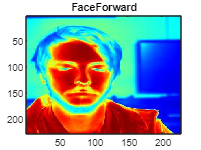


% ------------------------------------------------------
% Let's go into an infinite loop so we can read the 
% Webcame video and make guesses on images captured, we
% will need to control-C to stop program 
% ------------------------------------------------------
% while 1   
    
nMaxIterations = 100;

for nLoopingCounter = 1:nMaxIterations 
    
  % Capture Single frames
  myImage=getsnapshot(vid);  
 
  
  % Resize Image to 227x227 (algorithms are expecting this size image) 
  NewImage_227x227 = imresize(myImage,[227 227]);   

  % Allow colormapping
  oneChannel = NewImage_227x227(:,:,1)
  imwrite(oneChannel,jet,"mappedImage.jpg")
  finalImage = imread("mappedImage.jpg")
  
  % let's show the image in a window on the screen
  image(finalImage)
  
  

  % Use Trained Model to make prediction for current image
  [labelIdx, score] = predict(newCategoryClassifier, finalImage);   
  
  sprintf("Iteration: %d,  Current Guess: %d, PreviousGuess: %d", ...
      nLoopingCounter, labelIdx, PreviousGuessCounter);
  
  if (labelIdx == PreviousGuess)
      PreviousGuessCounter = PreviousGuessCounter + 1;
  else
      PreviousGuessCounter = 0;
  end
  
  % If we have 'n' consecutive guesses that are the same, then printout what
  % the guess is. This should keep intermediate incorrect guesses from showing up 
  if (PreviousGuessCounter > nNumberOfConsecutiveSameGuessesNeeded)
      % Use Label ID number of what the 'guess' was to get a text description of the 'guess' 
      newCategoryClassifier.Labels(labelIdx);
  end
  PreviousGuess = labelIdx;
%   title({char(label),num2str(max(score),2)});

title(newCategoryClassifier.Labels(labelIdx))
end

stop(vid);